# Spectral clustering of $R^n$ data

## Data

### 1D data

First data we consider is a simple 1D data represented by a histogram.

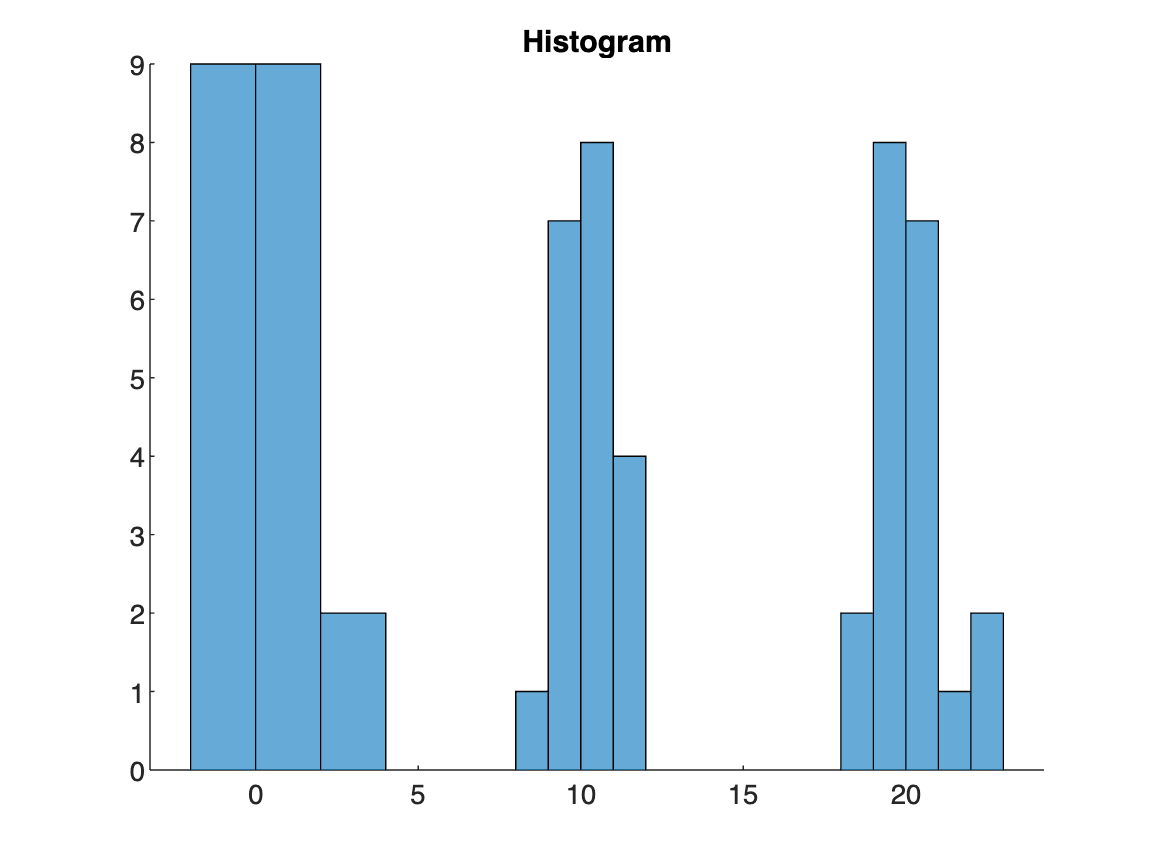

rng(4);
Z=[normrnd(0,1,[1,20]),...
normrnd(10,1,[1,20]),...
normrnd(20,1,[1,20])]';
figure
hold on
histogram(Z(1:20),'FaceColor','#0072BD')
histogram(Z(21:40),'FaceColor','#0072BD')
histogram(Z(41:60),'FaceColor','#0072BD')
title('Histogram')
hold off

### 2D data

Next, a well separated 2D data.

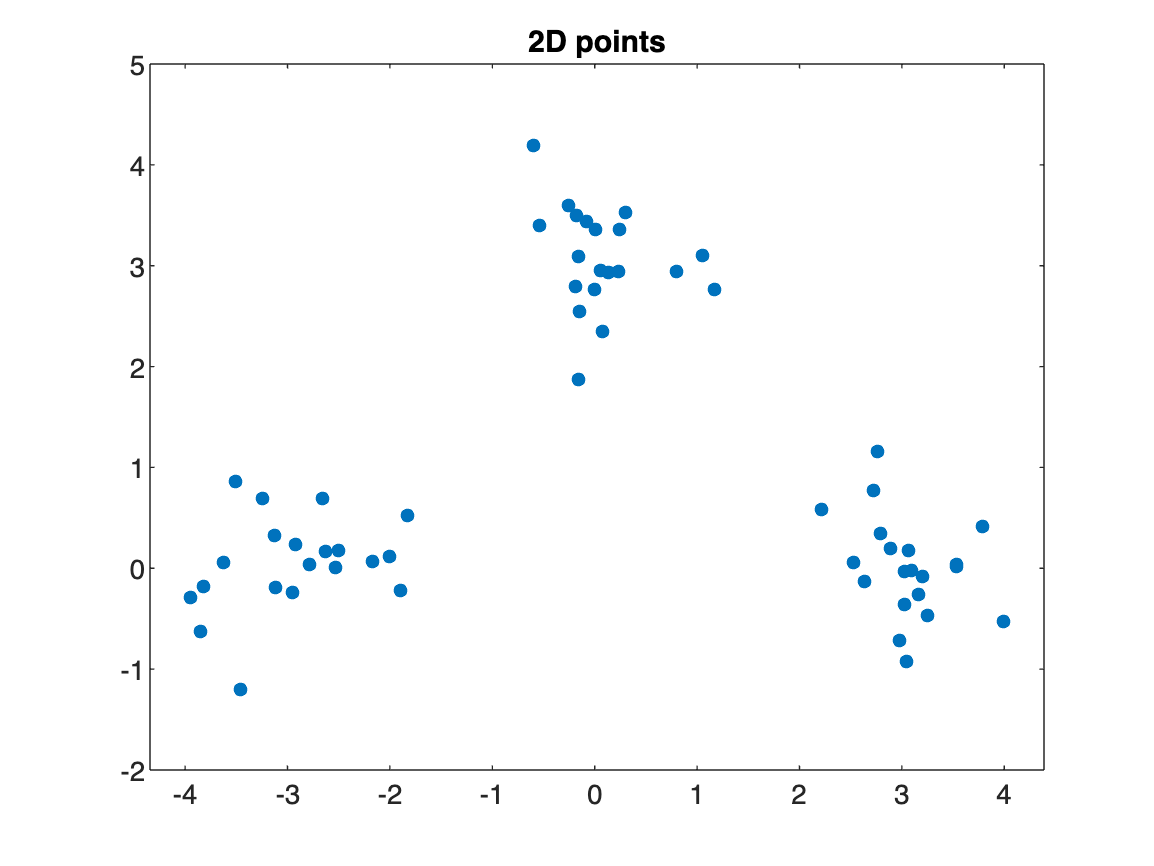

rng(4);
X=[normrnd(-3,0.5,[1,20]),...
normrnd(3,0.5,[1,20]),...
normrnd(0,0.5,[1,20]);

normrnd(0,0.5,[1,20]),...
normrnd(0,0.5,[1,20]),...
normrnd(3,0.5,[1,20]);
]';
X1=X(:,1); X2=X(:,2);
gscatter(X1,X2,'','','')
title('2D points');
legend('off');
xlabel('')
ylabel('')

### Spiral data

This is a classic data that most linear discriminant methods can not solve. It is often used in neural network examples.

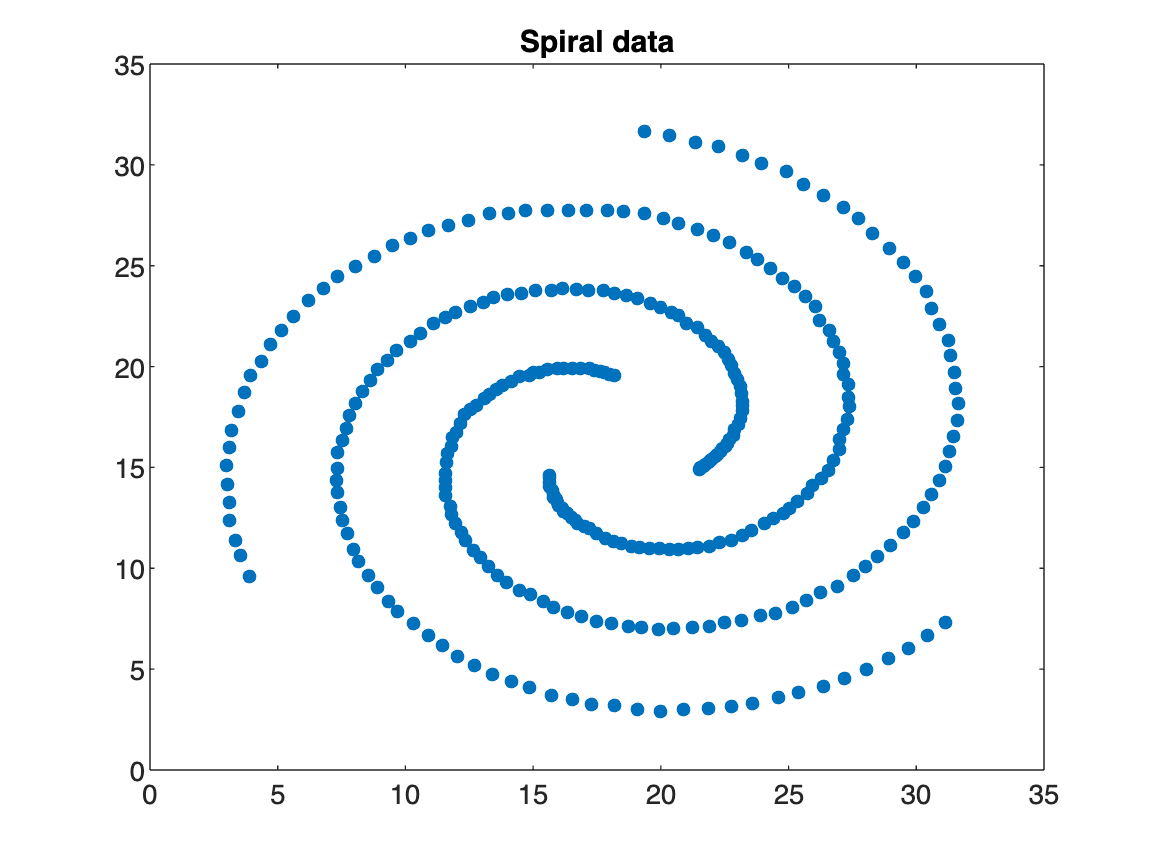

A = csvread('spiral.csv',1);
G=round(A(:,3));
A=A(:,1:2);
A1=A(:,1);
A2=A(:,2);
gscatter(A(:,1),A(:,2),'','','');
title('Spiral data');

### Ring data

This data is the most challenging for two reasons. The first is the size of the dataset, and the second is the fact that by trying to adjust parameters for any given ring we are likely to lose the ability to correctly detect the others using spectral clustering methods. More on this later.

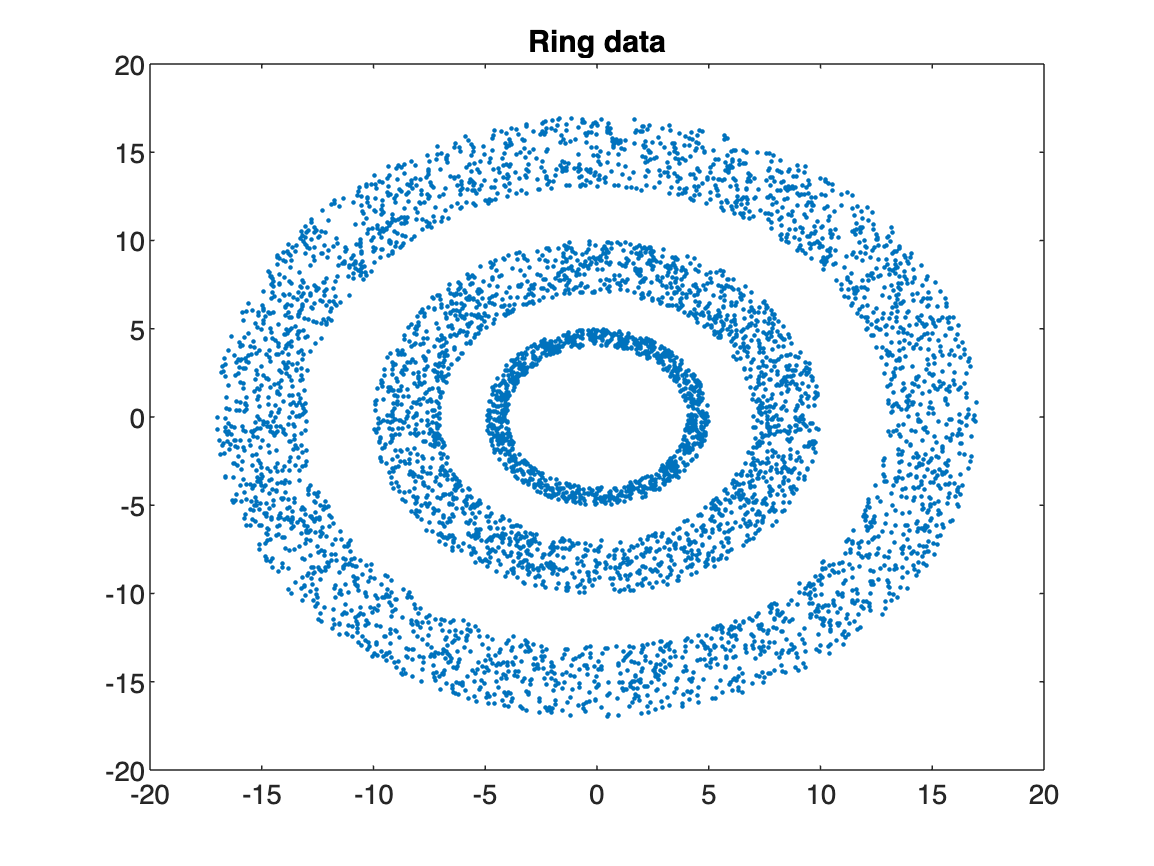

rng(4);

R1=unifrnd(4,5,1,1000);
theta1=unifrnd(0,2*pi,1,1000);

R2=unifrnd(7,10,1,2000);
theta2=unifrnd(0,2*pi,1,2000);

R3=unifrnd(13,17,1,3000);
theta3=unifrnd(0,2*pi,1,3000);

GK=[ones(1,1000), 2*ones(1,2000),3*ones(1,3000)];

K1=[R1.*cos(theta1),R2.*cos(theta2),R3.*cos(theta3)]'; K2=[R1.*sin(theta1),R2.*sin(theta2),R3.*sin(theta3)]';
K=[K1,K2];
gscatter(K1,K2,'','','')
title('Ring data');
xlabel('')
ylabel('')

## Itertive k-means

Let's attempt to cluster, or rather classify, the data correctly using the iterative k-means.

### 1D data

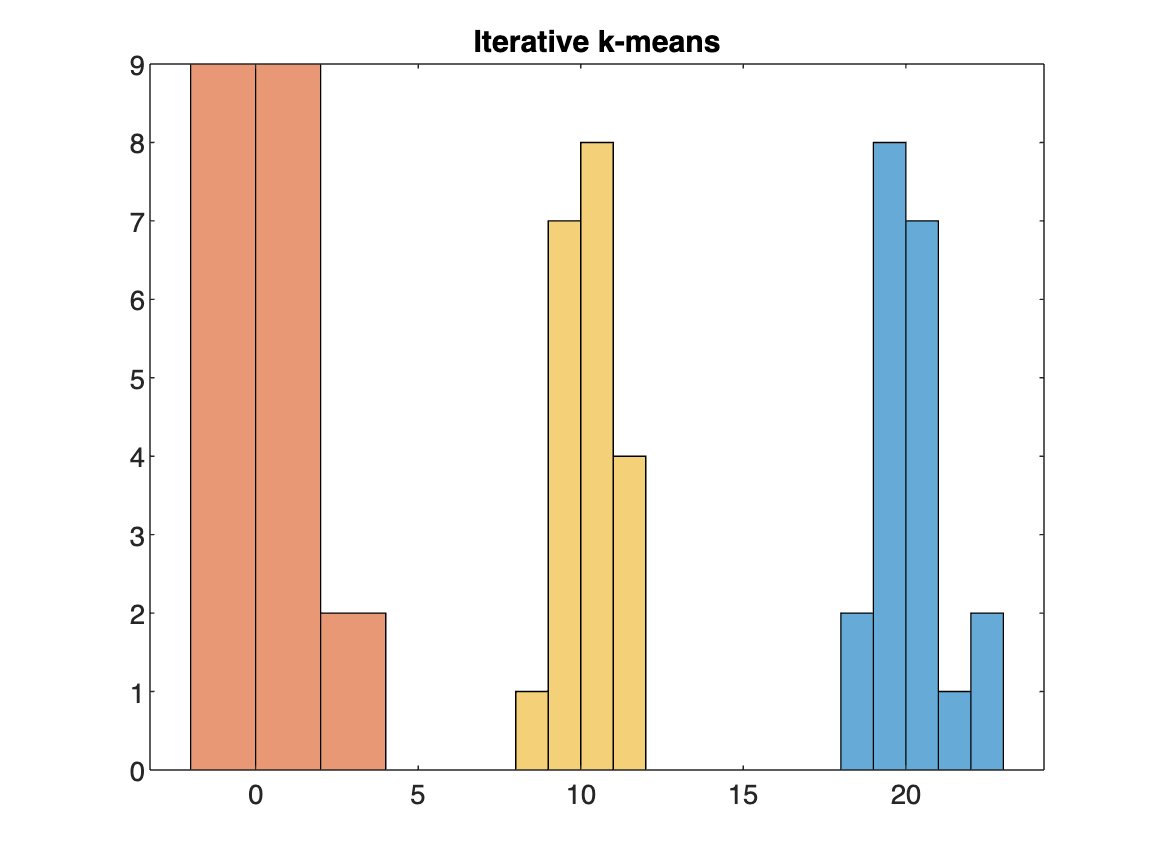

P=iterative_k_means(Z,3);
histogram(Z(P==1))
hold on
histogram(Z(P==2))
histogram(Z(P==3))
title('Iterative k-means')
hold off

### 2D data

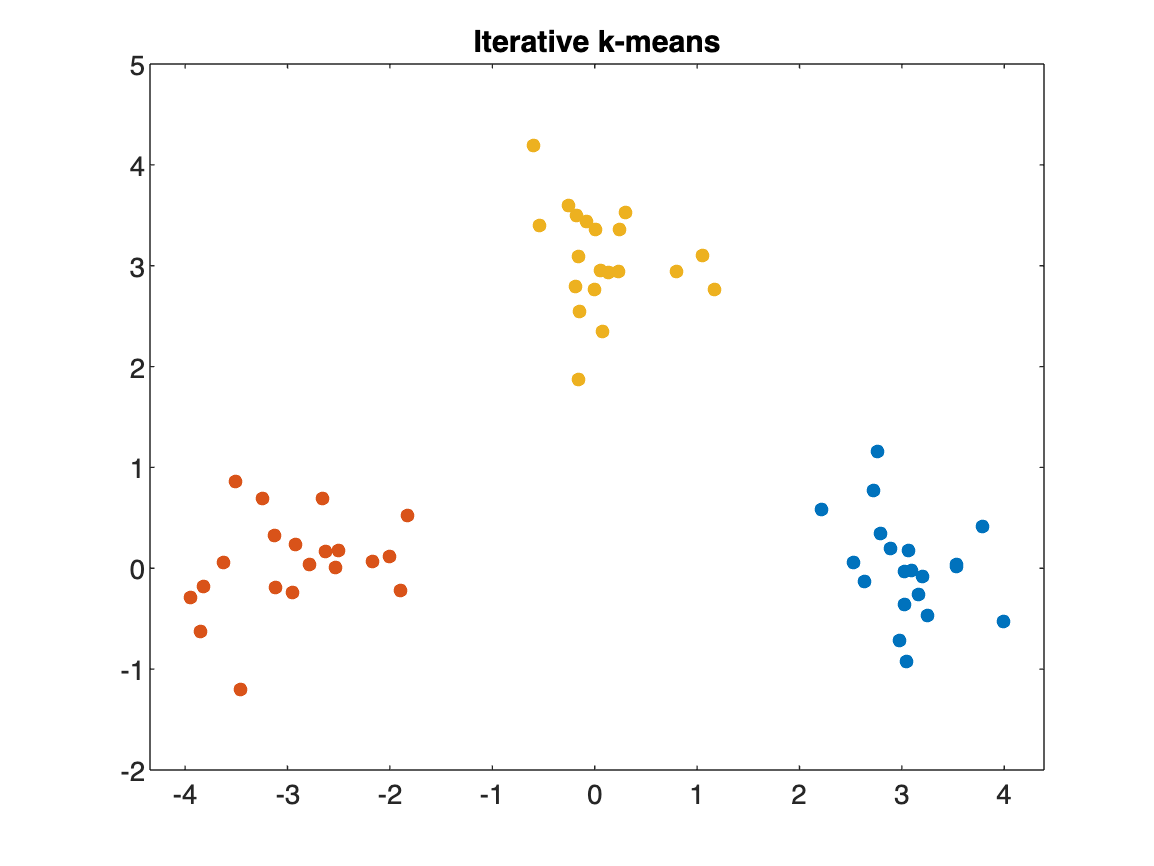

P=iterative_k_means(X,3);
gscatter(X1,X2,P,'','') 
title('Iterative k-means');
legend('off');
xlabel('')
ylabel('')

### Spiral data

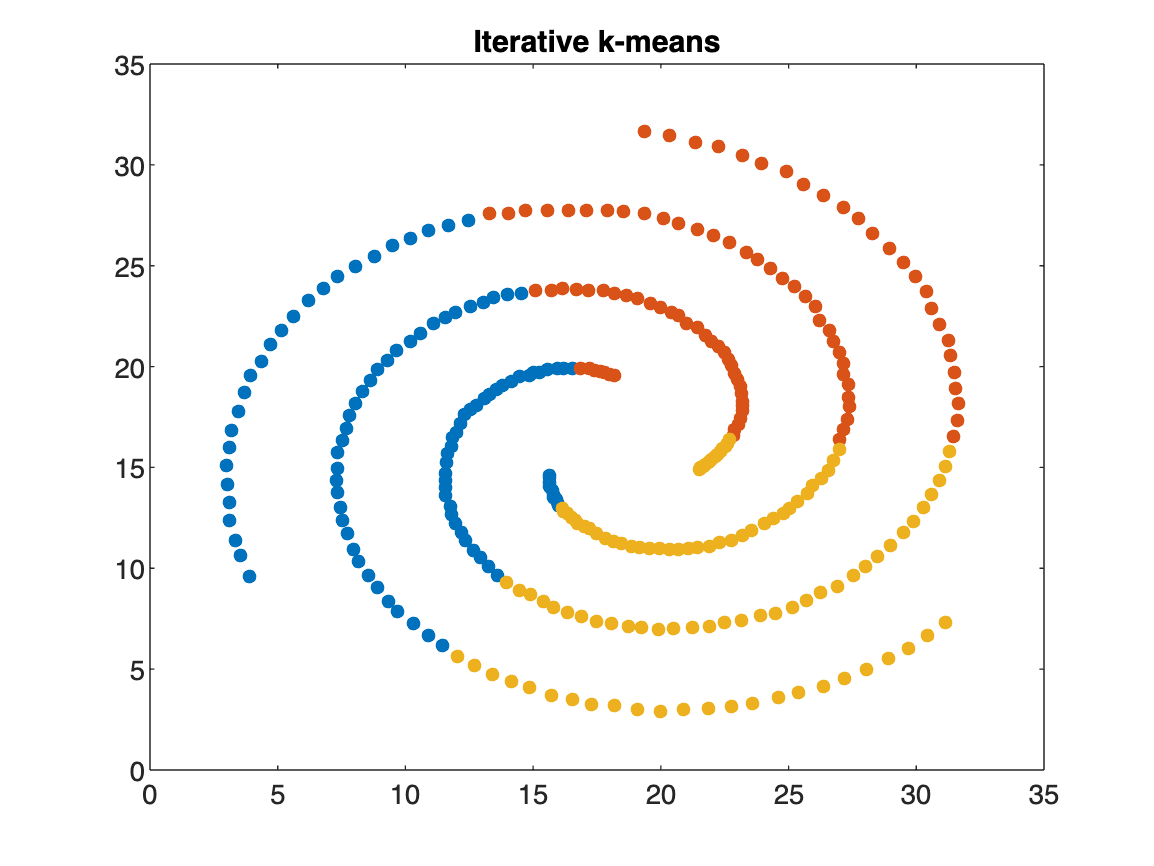

P=iterative_k_means(A,3);
gscatter(A1,A2,P,'','') 
title('Iterative k-means');
legend('off');
xlabel('')
ylabel('')

### Ring data

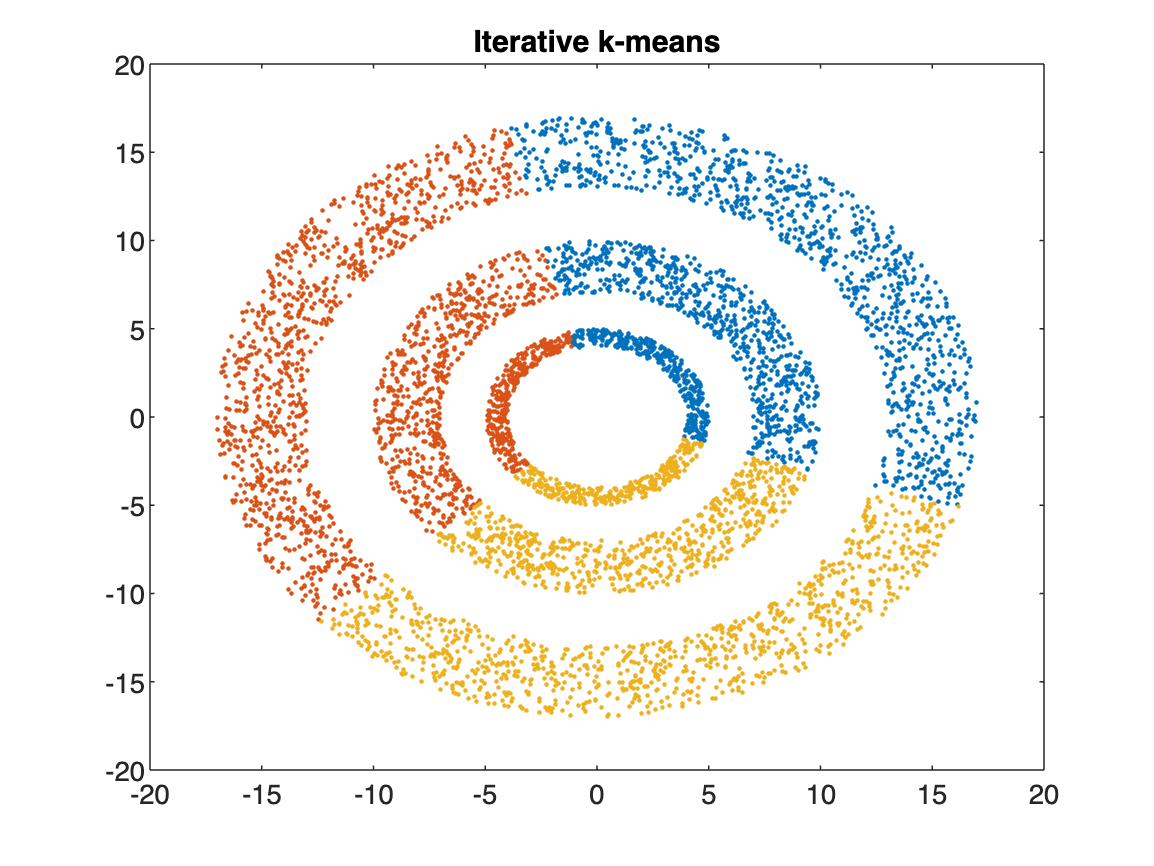

P=iterative_k_means(K,3);
gscatter(K1,K2,P,'','') 
title('Iterative k-means');
legend('off');
xlabel('')
ylabel('')

### Conclusion

Circles and spirals cannot be classified correctly using simple k-means algorithm. There is no way to detect the structure in the data. We need some new methods!

# Spectral clustering with Gaussian kernels, 1D data

## Unnormalized Laplacian

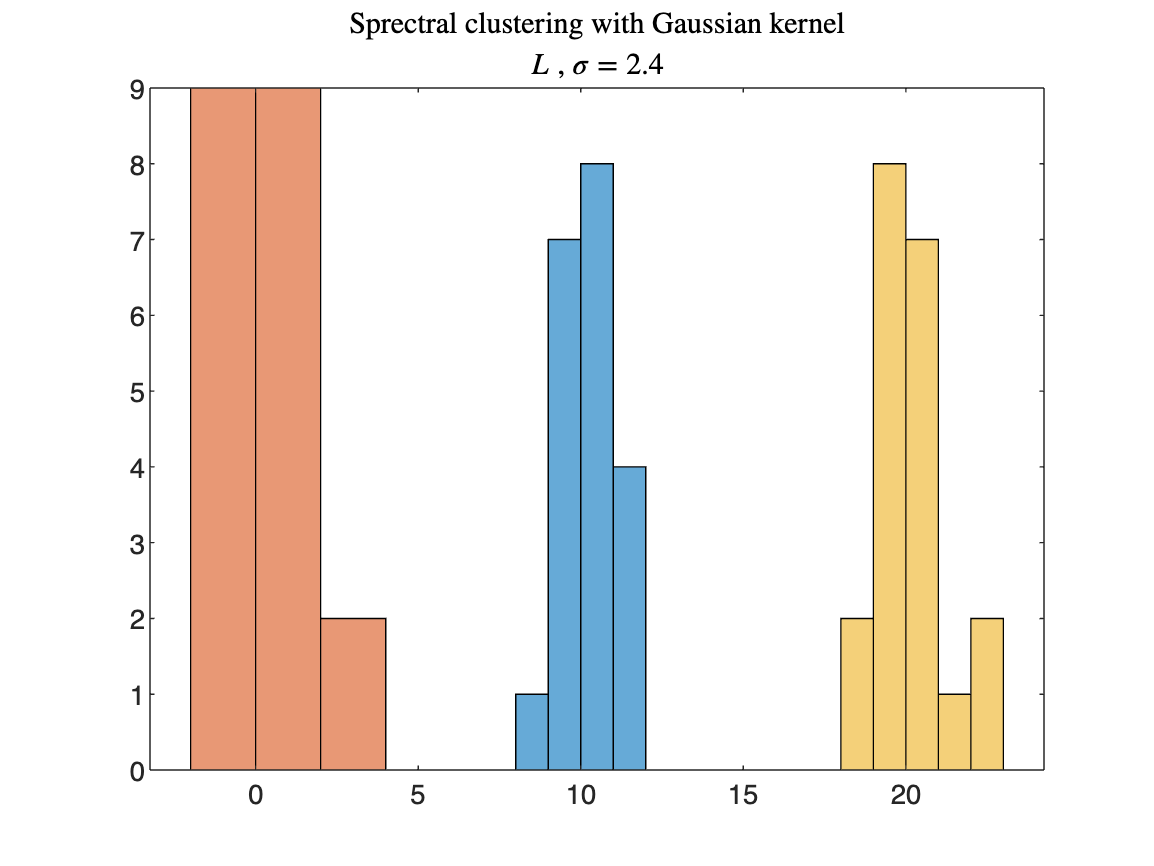

P=laplacian(gaussian_kernel(Z,2.4),3);
histogram(Z(P==1))
hold on
histogram(Z(P==2))
histogram(Z(P==3))
title('Sprectral clustering with Gaussian kernel', ...
    '$L$ , $\sigma = 2.4$','interpreter','latex' ...
    )
hold off

## Symetric Laplacian

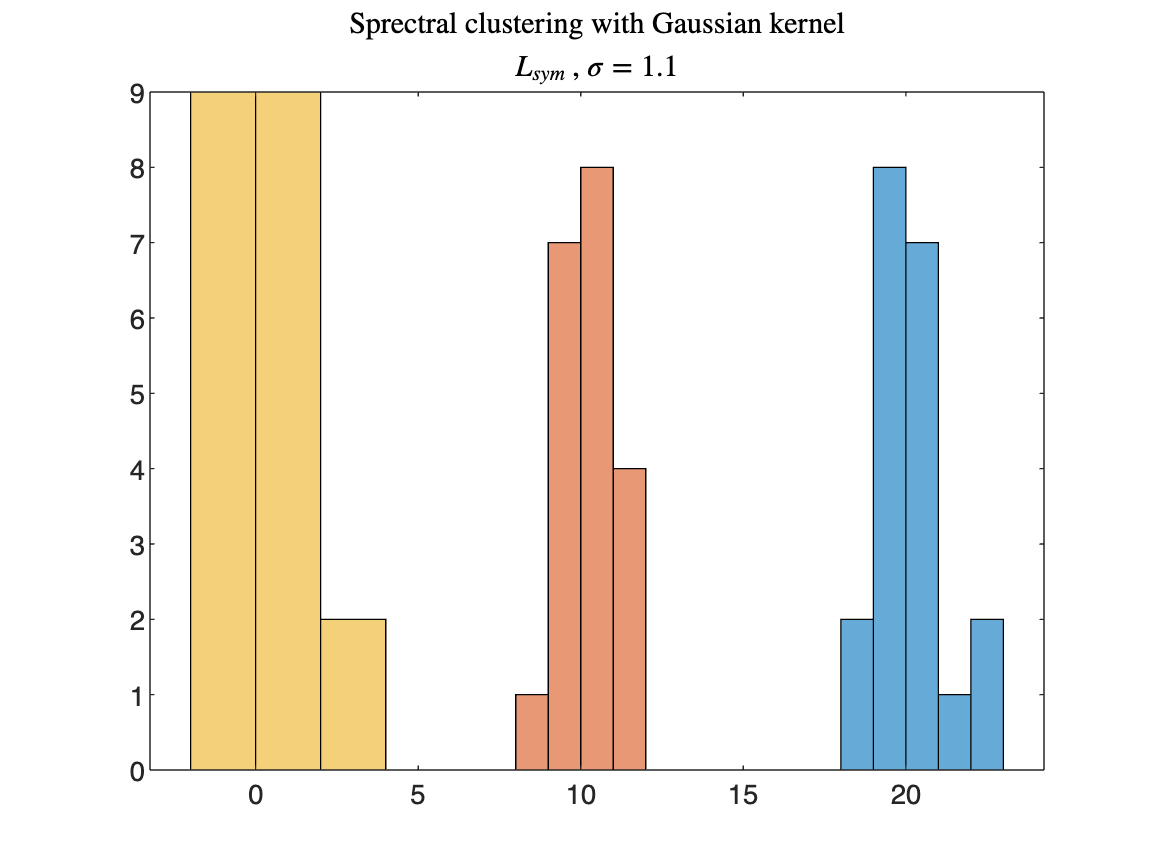

P=laplacian_sym(gaussian_kernel(Z,1.1),3);
histogram(Z(P==1))
hold on
histogram(Z(P==2))
histogram(Z(P==3))
title('Sprectral clustering with Gaussian kernel', ...
    '$L_{sym}$ , $\sigma = 1.1$','interpreter','latex' ...
    )
hold off

## Normalized Laplacian

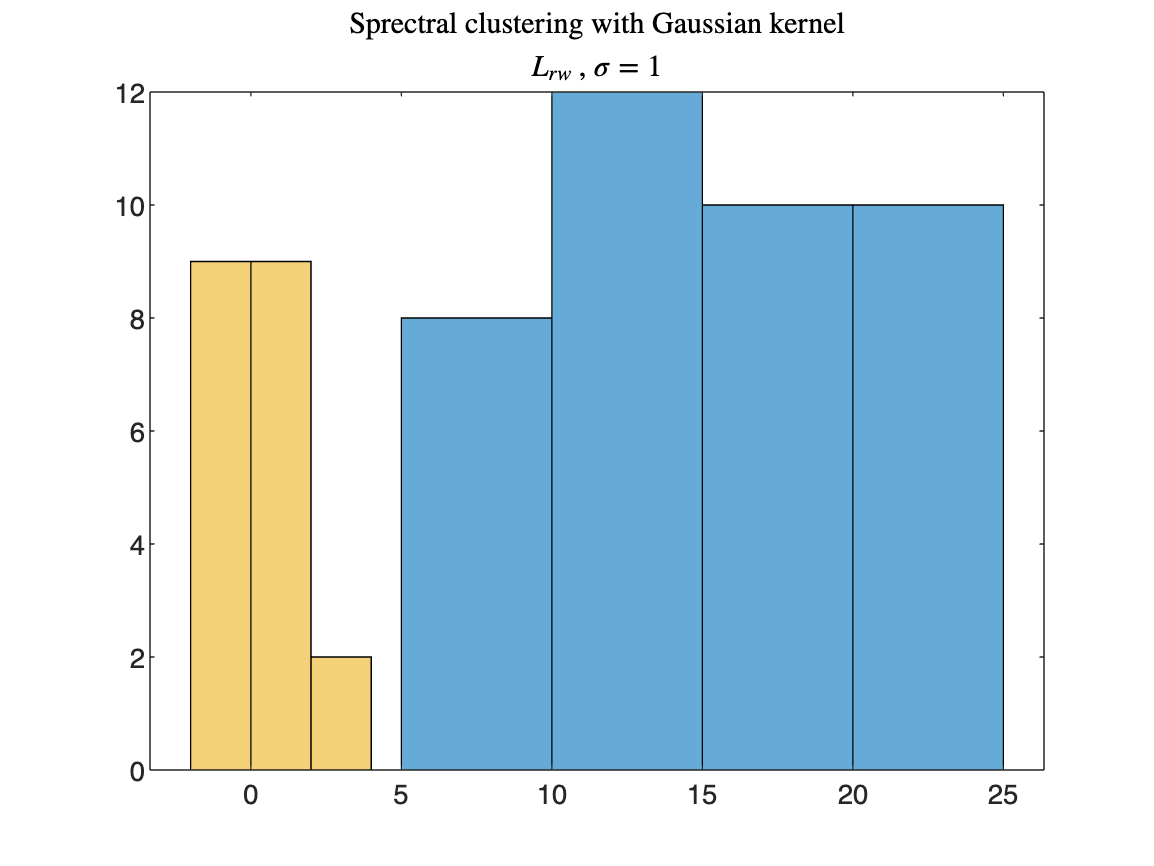

P=laplacian_rw(gaussian_kernel(Z,1),3);
histogram(Z(P==1))
hold on
histogram(Z(P==2))
histogram(Z(P==3))
title('Sprectral clustering with Gaussian kernel', ...
    '$L_{rw}$ , $\sigma = 1$','interpreter','latex' ...
    )
hold off

## Normalized cuts

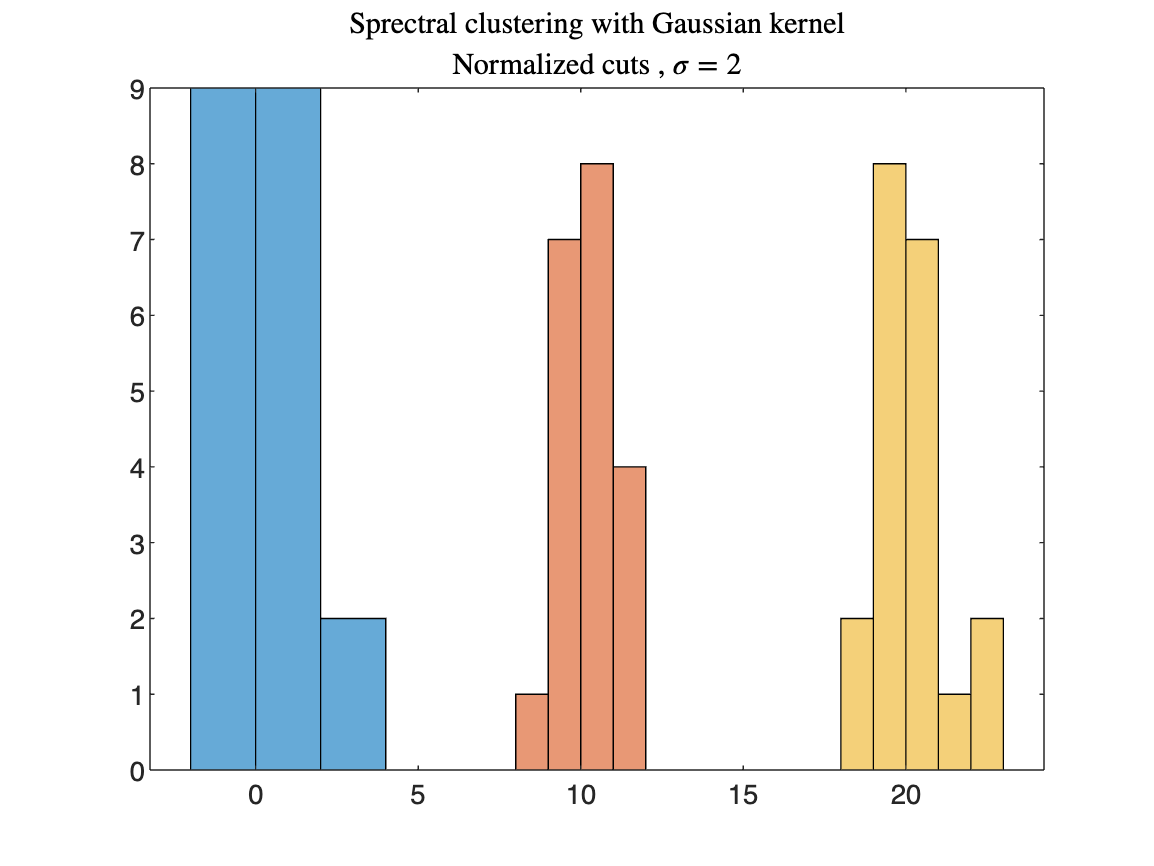

P=normalized_cuts(gaussian_kernel(Z,2),3);
histogram(Z(P==1))
hold on
histogram(Z(P==2))
histogram(Z(P==3))
title('Sprectral clustering with Gaussian kernel', ...
    'Normalized cuts , $\sigma = 2$','interpreter','latex' ...
    )
hold off

### Conclusion

Spectral clustering seems to work well on 1D data.

# Spectral clustering with Gaussian kernels, 2D data

## Unnormalized Laplacian

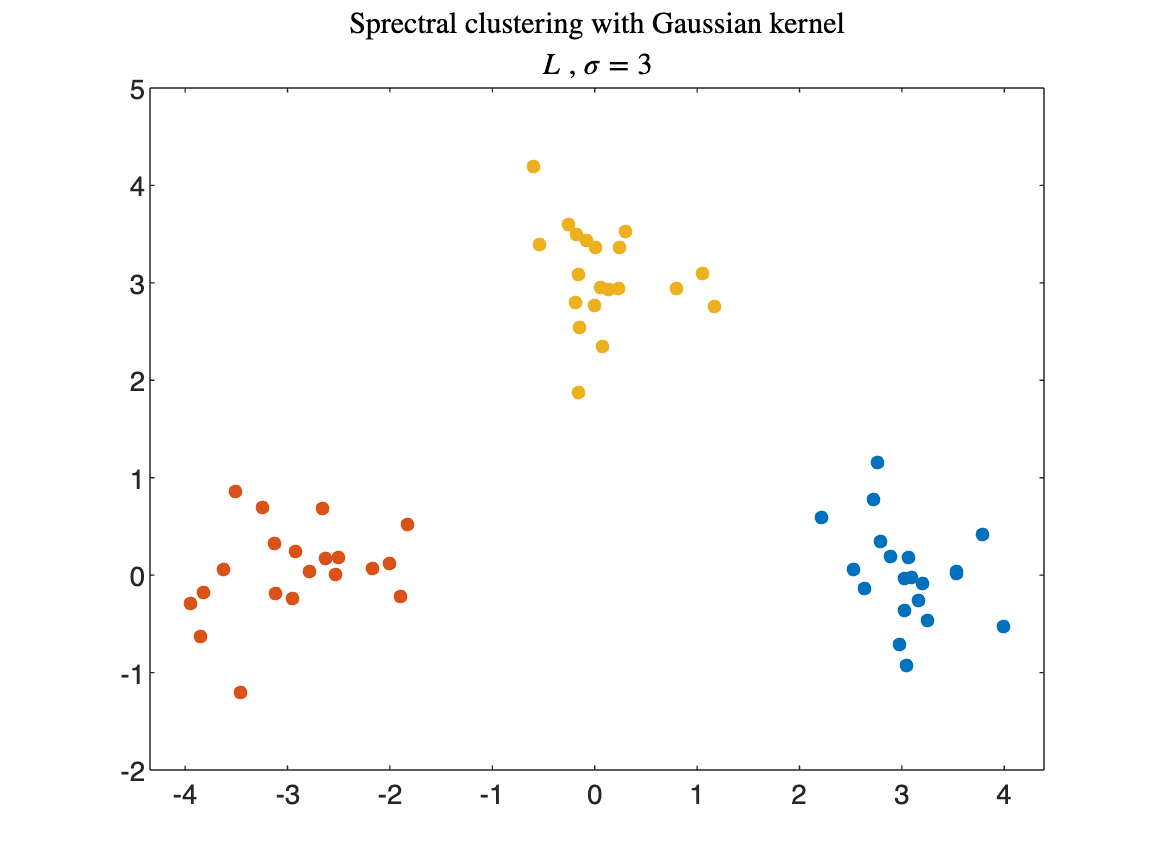

P=laplacian(gaussian_kernel (X,3),3);
gscatter(X1,X2,P,'','') 
title('Sprectral clustering with Gaussian kernel', ...
    '$L$ , $\sigma = 3$','interpreter','latex' ...
    )
legend('off');
legend('off');
xlabel('')
ylabel('')

## Symetric Laplacian

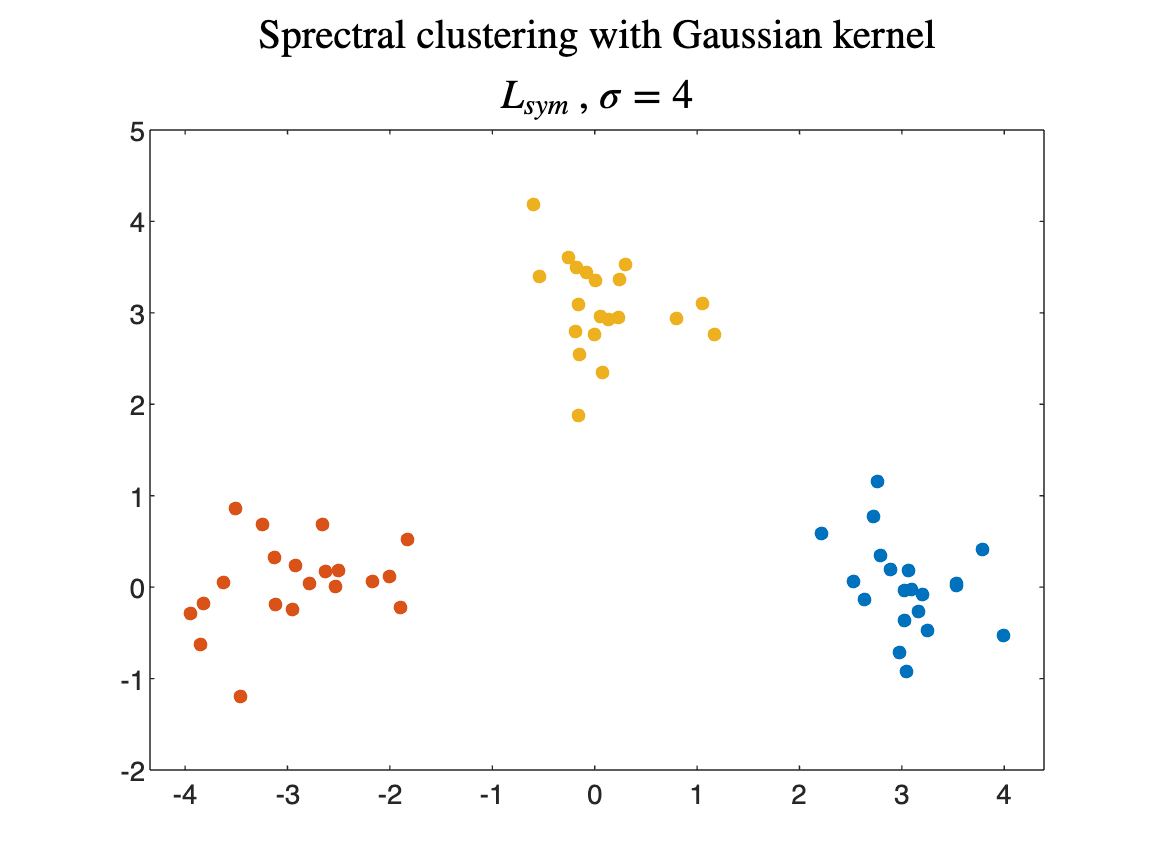

P=laplacian_sym(gaussian_kernel (X,4),3);
gscatter(X1,X2,P,'','') 
title('Sprectral clustering with Gaussian kernel', ...
    '$L_{sym}$ , $\sigma = 4$','interpreter','latex' ...
    ,FontSize=15)
legend('off'); 
xlabel('')
ylabel('')

## Normalized Laplacian

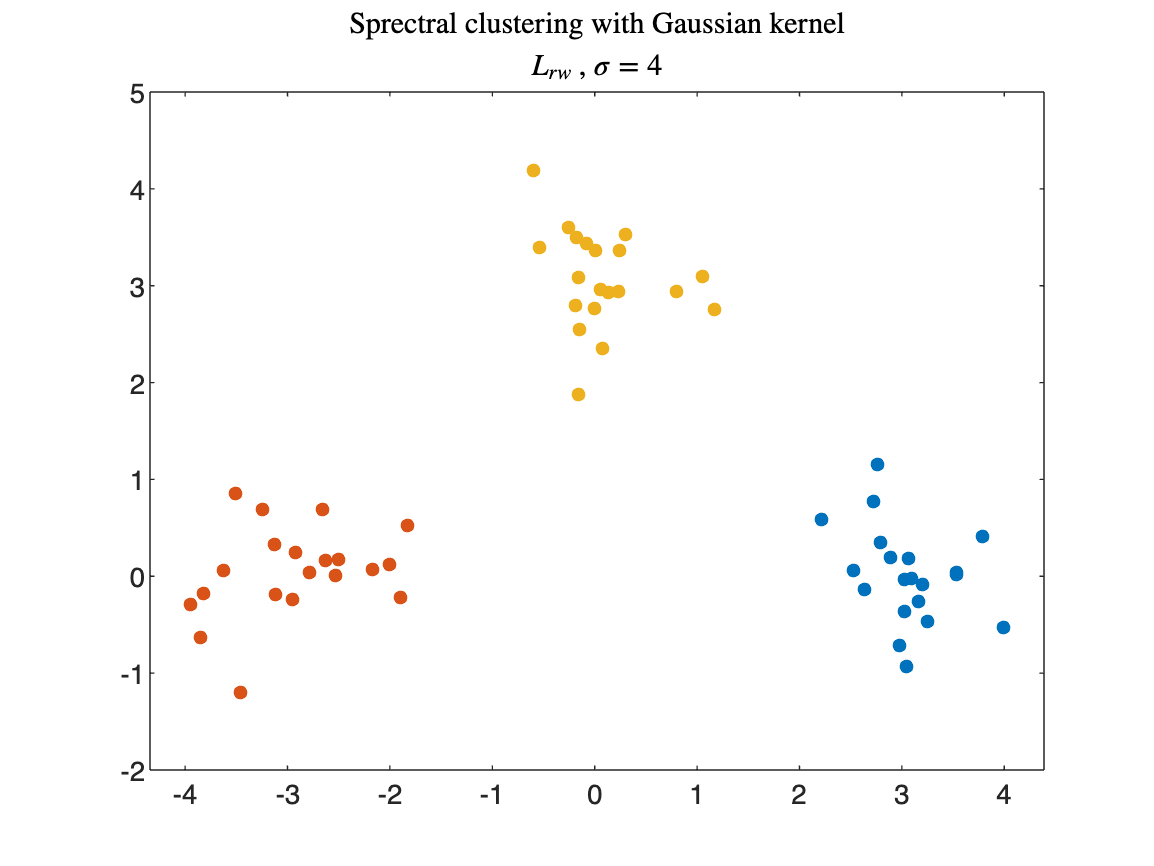

P=laplacian_rw(gaussian_kernel (X,4),3);
gscatter(X1,X2,P,'','') 
title('Sprectral clustering with Gaussian kernel', ...
    '$L_{rw}$ , $\sigma = 4$','interpreter','latex' ...
    )
legend('off');
xlabel('')
ylabel('')

## Normalized cuts

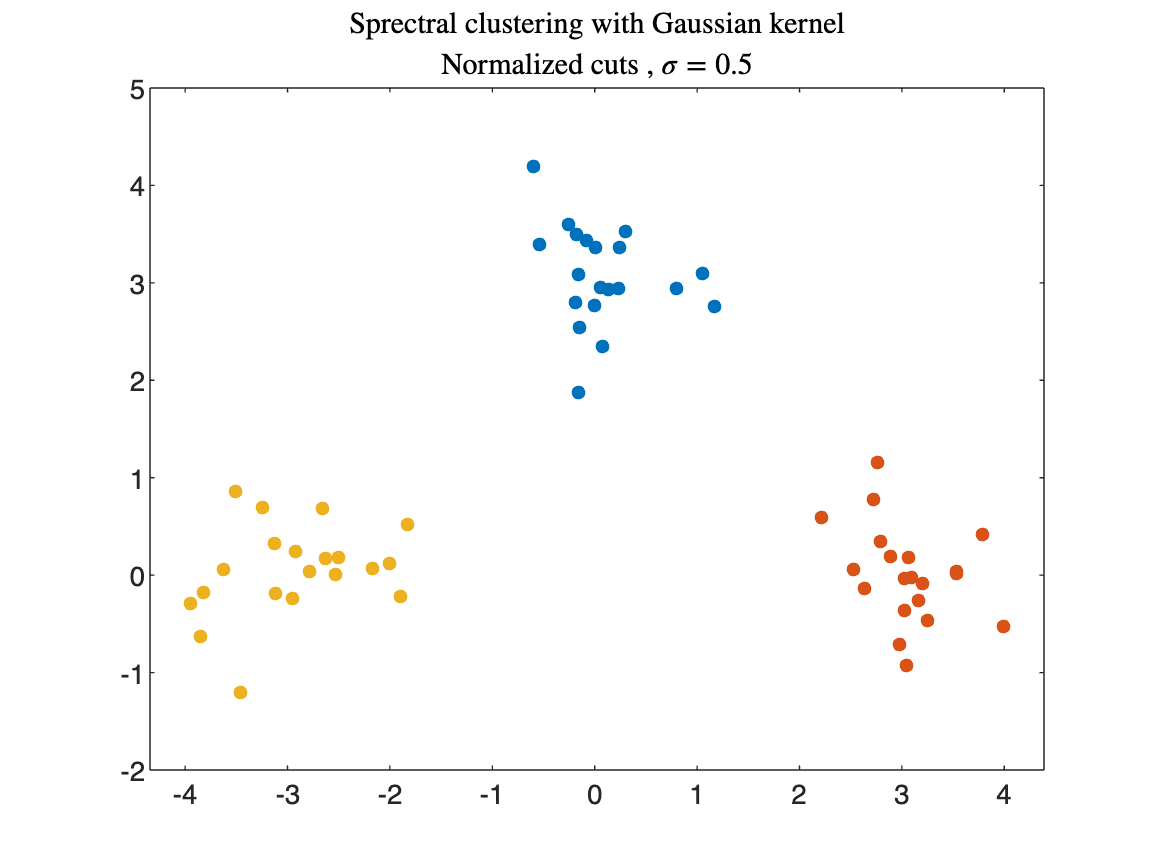

P=normalized_cuts(gaussian_kernel (X,0.5),3);
gscatter(X1,X2,P,'','') 
title('Sprectral clustering with Gaussian kernel', ...
    'Normalized cuts , $\sigma = 0.5$','interpreter','latex' ...
    )
legend('off');
xlabel('')
ylabel('')

### Conclusion

Spectral clustering is still preforming good, no worse than a simple k-means.

# Spectral clustering with Gaussian kernels,  Spiral data

## Unnormalized Laplacian

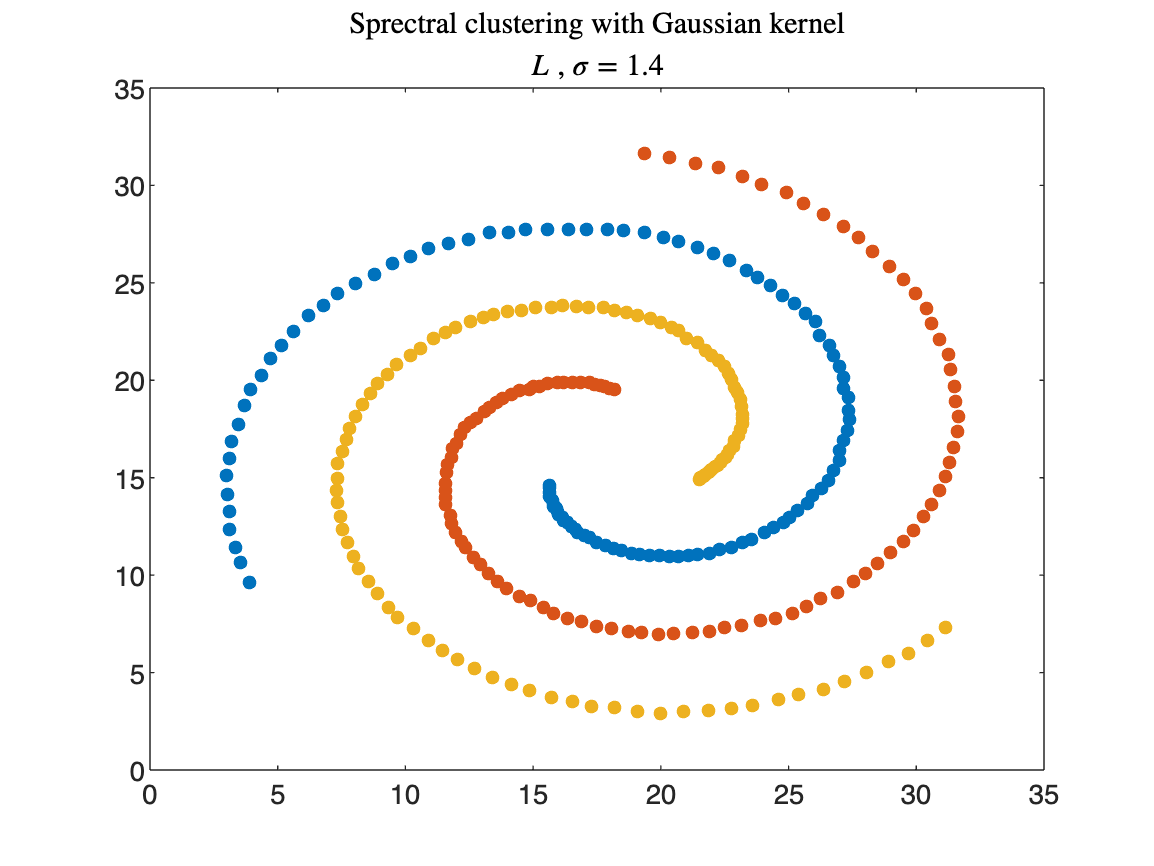

P=laplacian(gaussian_kernel (A,1.4),3);
gscatter(A1,A2,P,'','') 
title('Sprectral clustering with Gaussian kernel', ...
    '$L$ , $\sigma = 1.4 $','interpreter','latex' ...
    )
legend('off');
xlabel('')
ylabel('')

## Symetric Laplacian

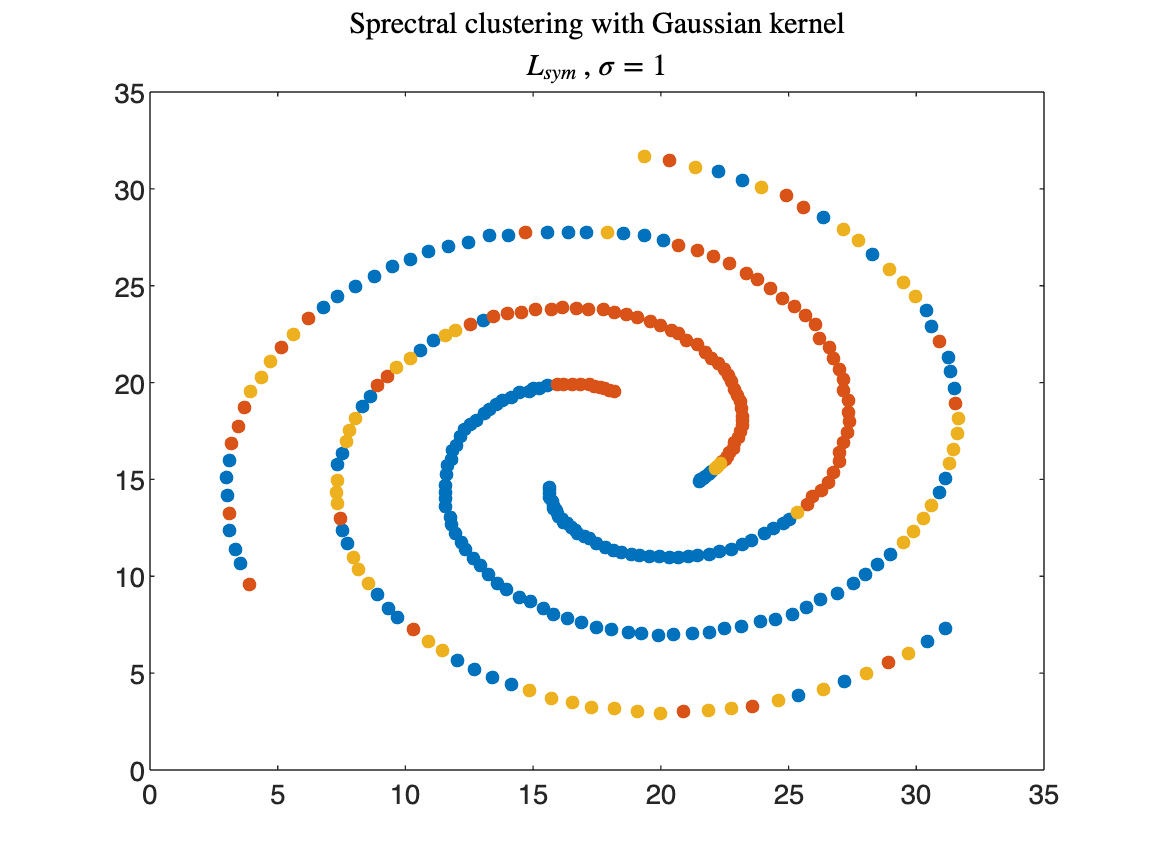

P=laplacian_sym(gaussian_kernel (A,1),3);
gscatter(A1,A2,P,'','') 
title('Sprectral clustering with Gaussian kernel', ...
    '$L_{sym}$ , $\sigma = 1$','interpreter','latex' ...
    )
legend('off');
xlabel('')
ylabel('')

## Normalized Laplacian

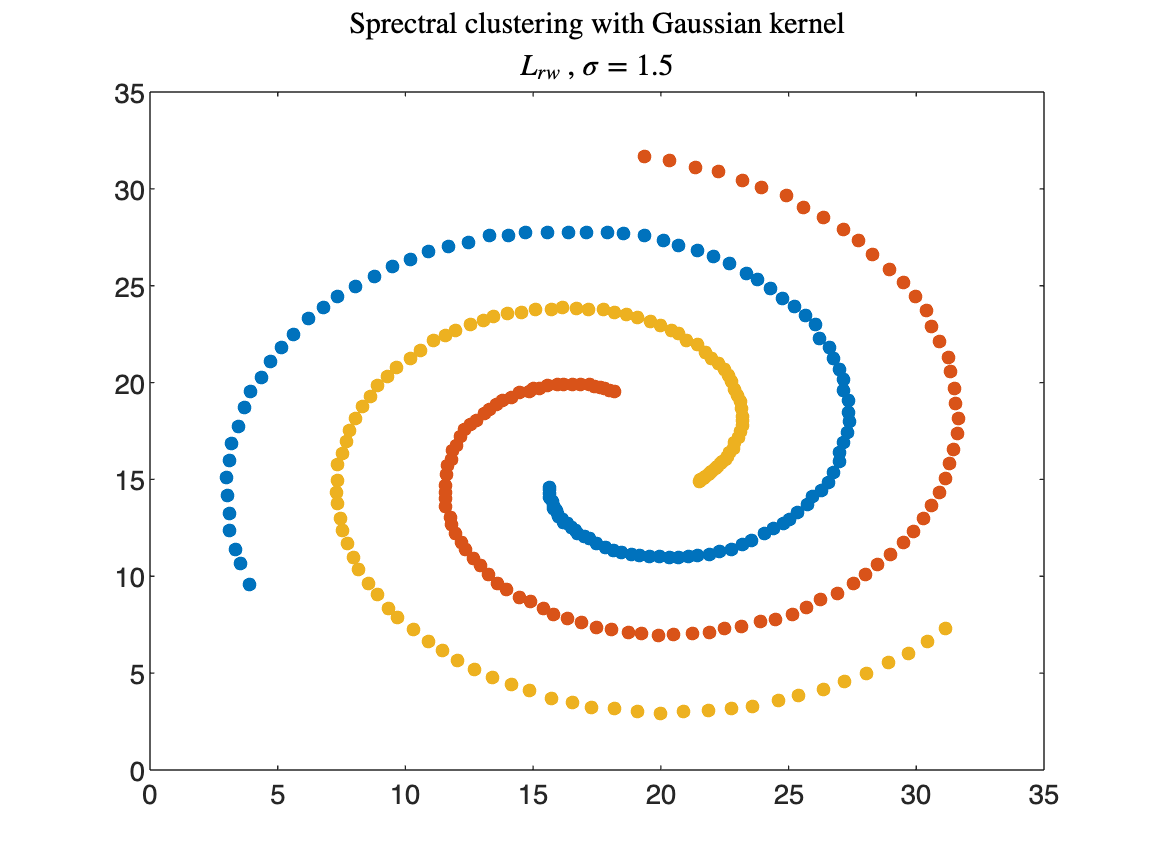

P=laplacian_rw(gaussian_kernel (A,1.5),3);
gscatter(A1,A2,P,'','') 
title('Sprectral clustering with Gaussian kernel', ...
    '$L_{rw}$ , $\sigma = 1.5 $','interpreter','latex' ...
    )
legend('off');
xlabel('')
ylabel('')

### Normalized cuts

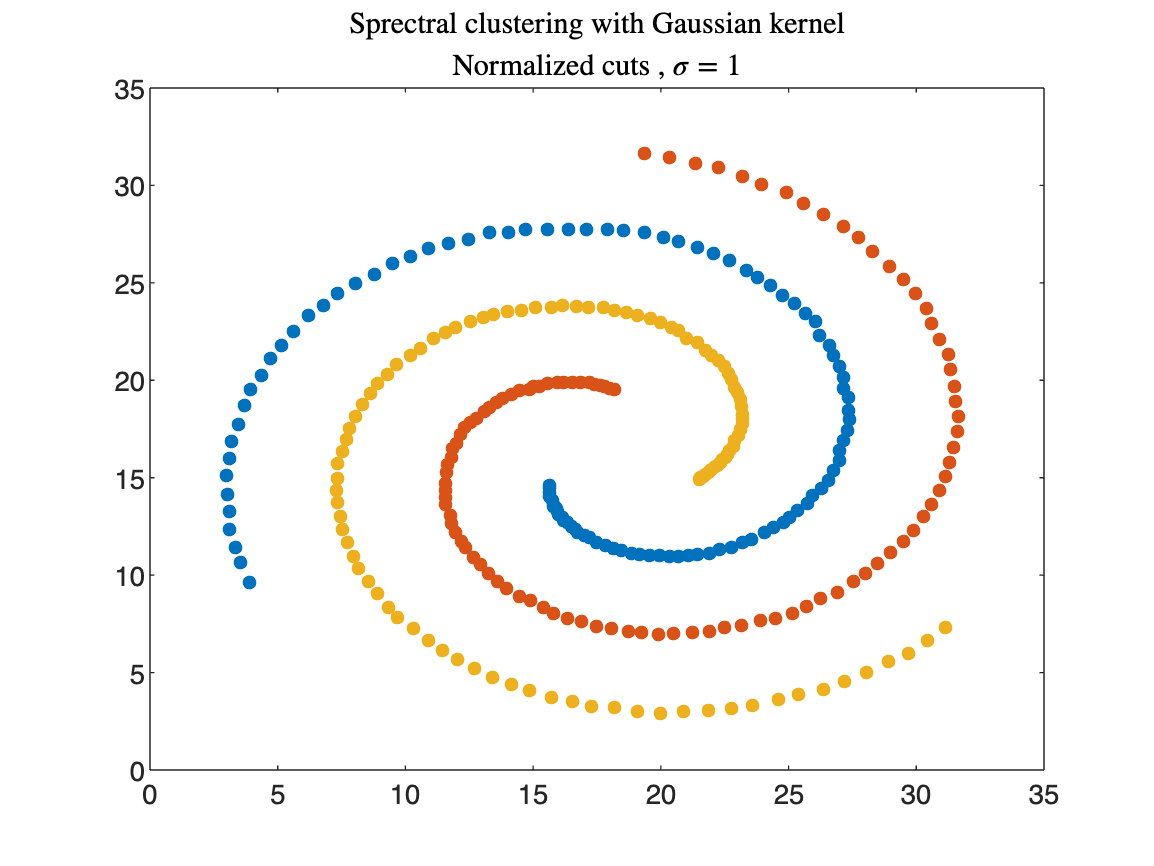

P=normalized_cuts(gaussian_kernel(A,1),3);
gscatter(A1,A2,P,'','') 
title('Sprectral clustering with Gaussian kernel', ...
    'Normalized cuts , $\sigma = 1$','interpreter','latex' ...
    )
legend('off');
xlabel('')
ylabel('')

### Conclusion

We have maneged to outpreform k-means and solve the problem of correctly identifying the clusters.

# Spectral clustering with Gaussian kernels, Ring data

## Unnormalized Laplacian

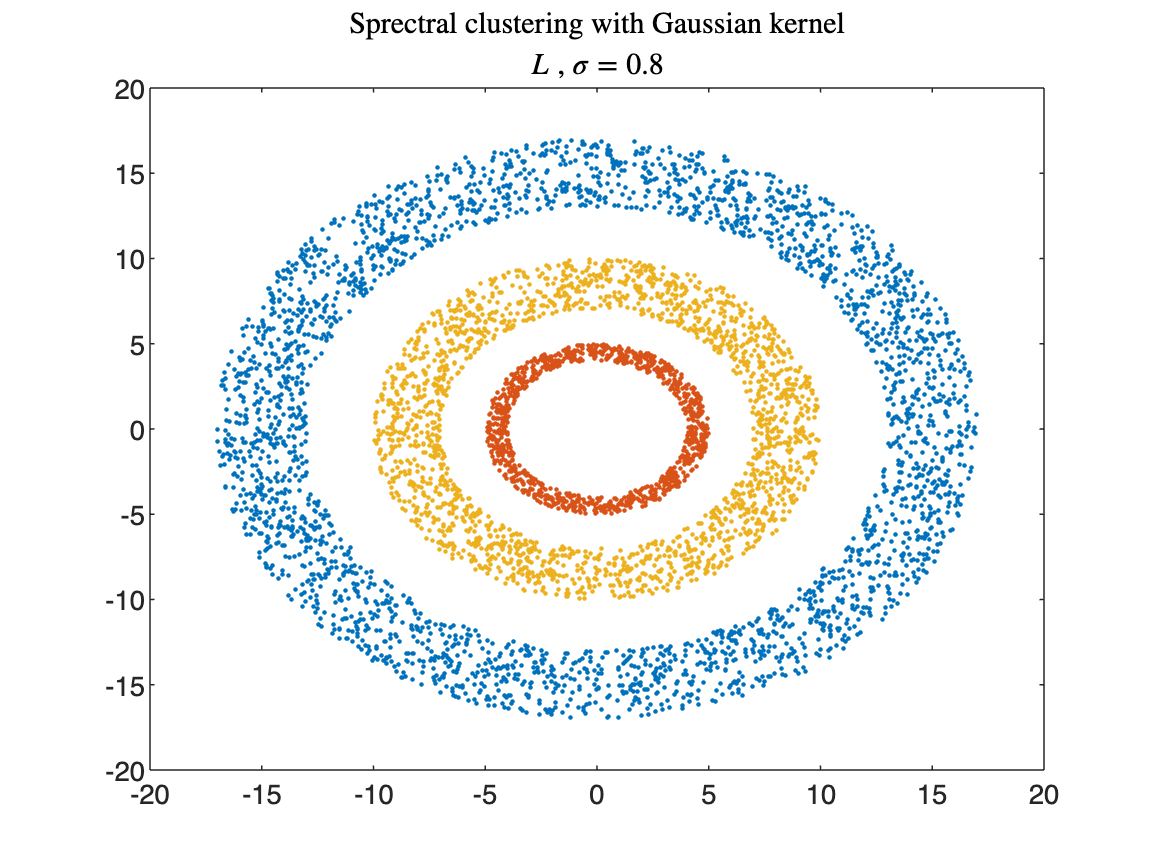

P=laplacian(gaussian_kernel (K,0.8),3);
gscatter(K1,K2,P,'','') 
title('Sprectral clustering with Gaussian kernel', ...
    '$L$ , $\sigma = 0.8$','interpreter','latex' ...
    )
legend('off');
xlabel('')
ylabel('')

## Symetric Laplacian

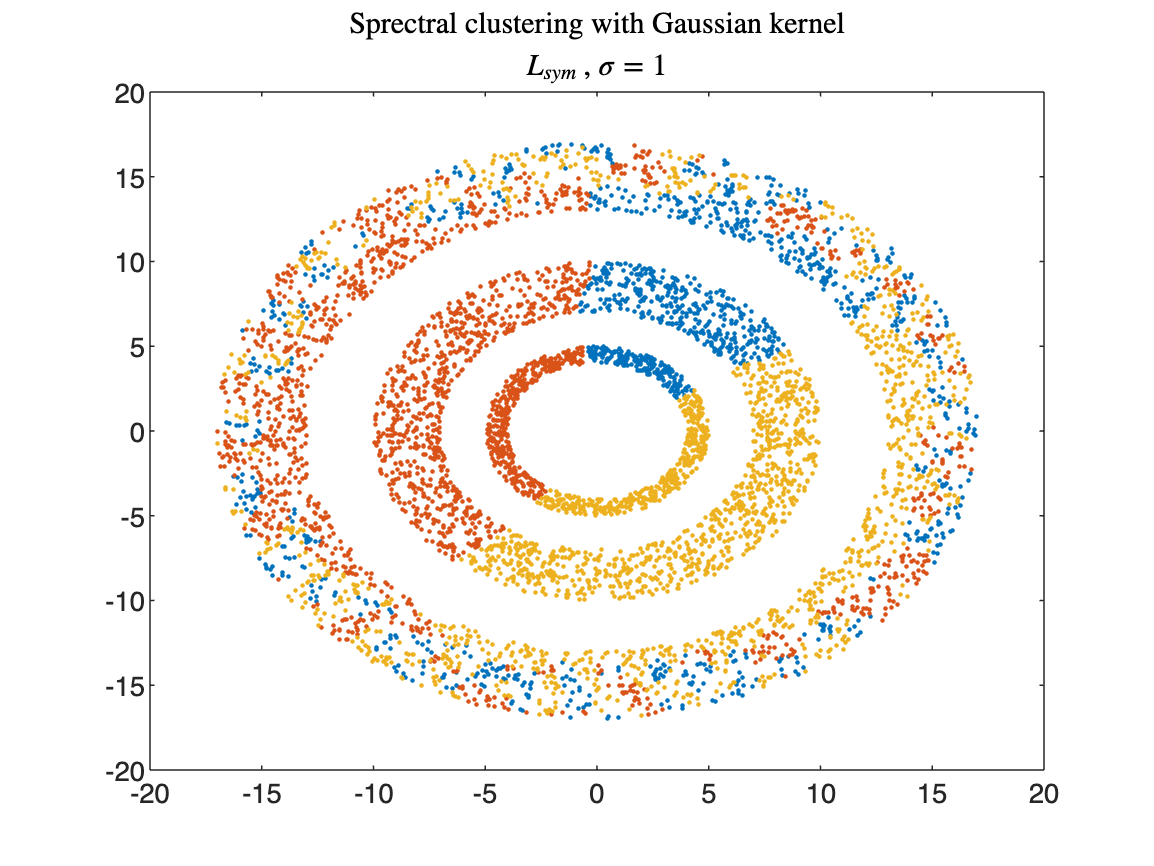

P=laplacian_sym(gaussian_kernel (K,1),3);
gscatter(K1,K2,P,'','') 
title('Sprectral clustering with Gaussian kernel', ...
    '$L_{sym}$ , $\sigma = 1$','interpreter','latex' ...
    )
legend('off');
xlabel('')
ylabel('')

## Normalized Laplacian

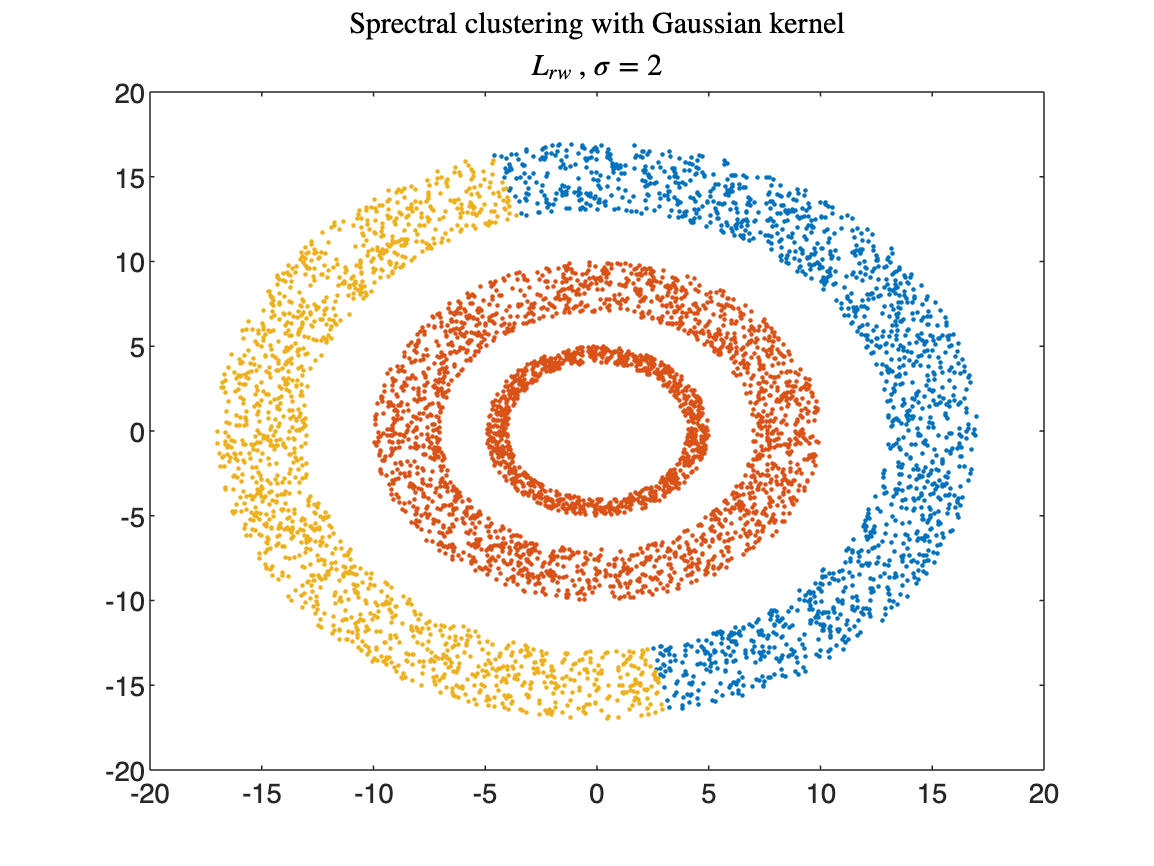

P=laplacian_rw(gaussian_kernel (K,2),3);
gscatter(K1,K2,P,'','') 
title('Sprectral clustering with Gaussian kernel', ...
    '$L_{rw}$ , $\sigma = 2$','interpreter','latex' ...
    )
legend('off');
xlabel('')
ylabel('')

## Normalized cuts

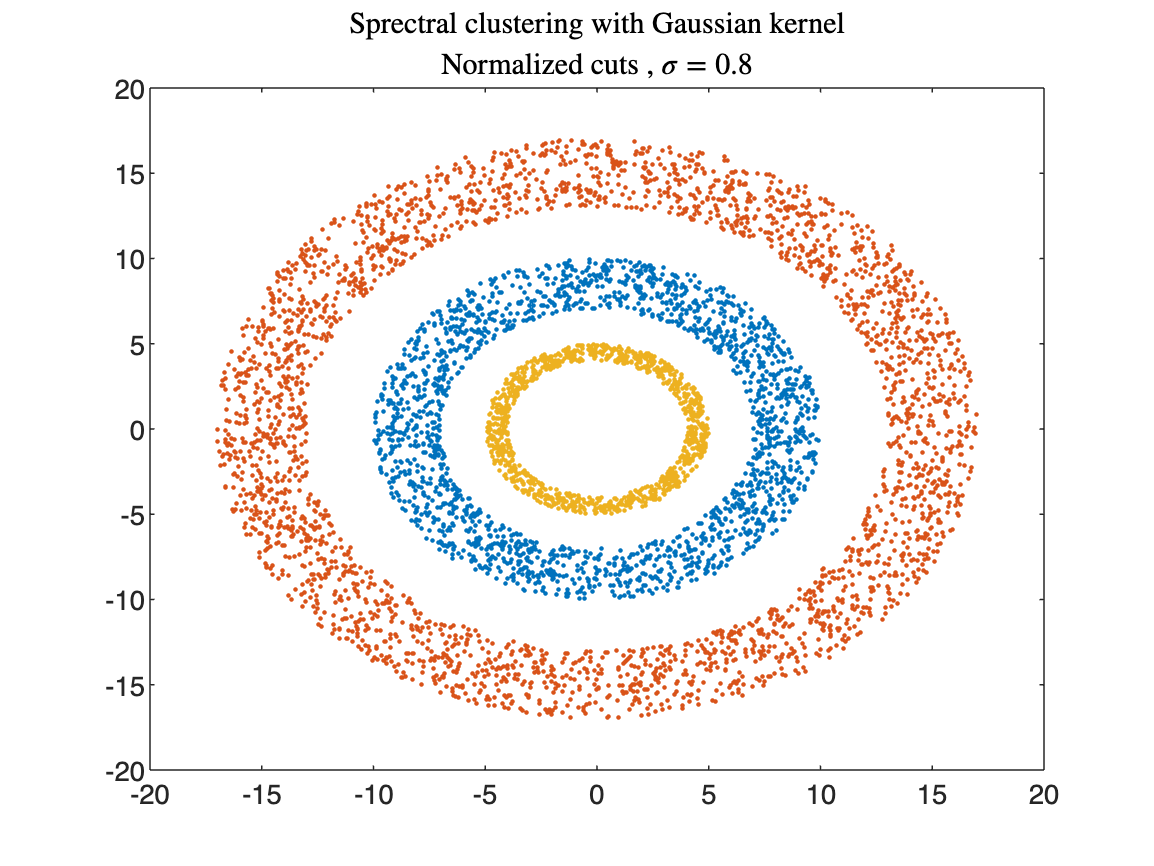

P=normalized_cuts(gaussian_kernel (K,0.8),3);
gscatter(K1,K2,P,'','') 
title('Sprectral clustering with Gaussian kernel', ...
    'Normalized cuts , $\sigma = 0.8$','interpreter','latex')
legend('off');
xlabel('')
ylabel('')

### Conclusion

With some dificulty in choosing the correct parameters we have even managed to correctly identify the three rings without using the labels. This shows how spectral clustering preforms very well in the unsupervised learning environment.

# Spectral clustering with $\epsilon - neighborhood$ kernels, 1D data

## Unnormalized Laplacian

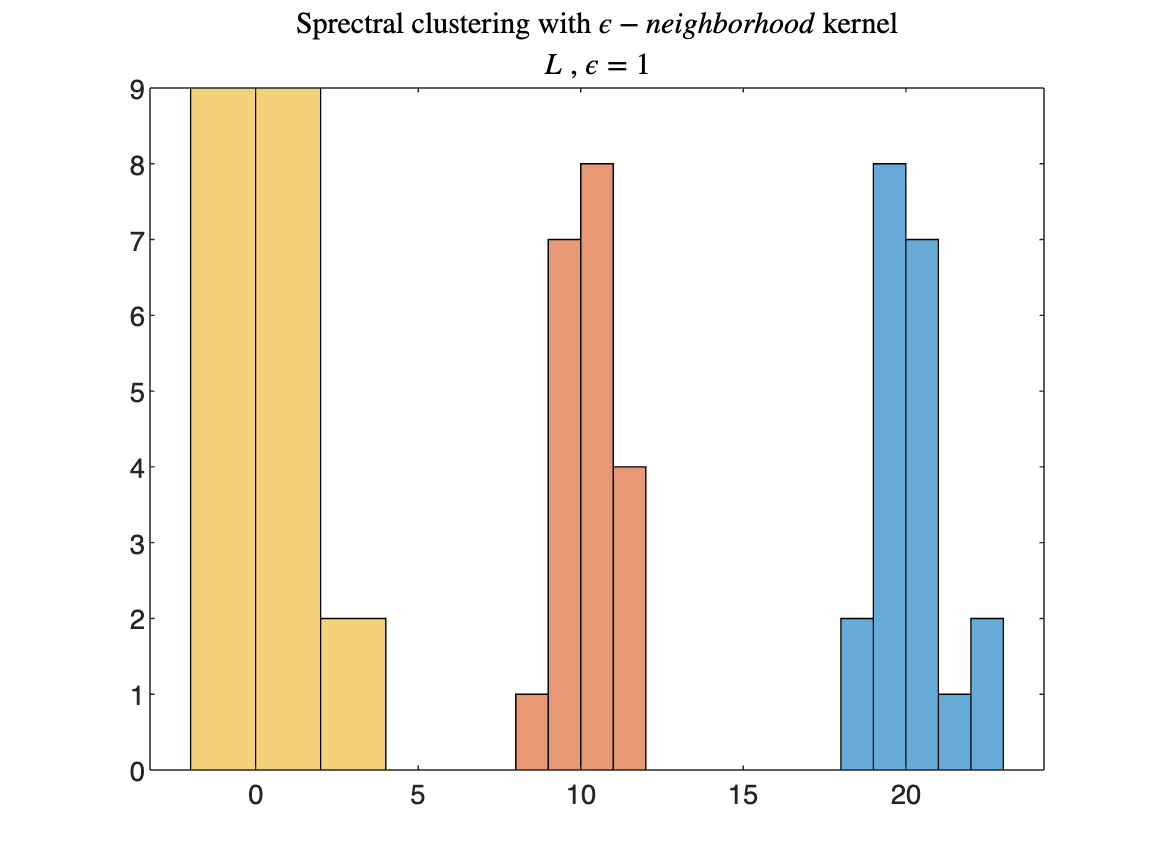

P=laplacian(epsilon_kernel(Z,1),3);
histogram(Z(P==1))
hold on
histogram(Z(P==2))
histogram(Z(P==3))
title('Sprectral clustering with  $\epsilon - neighborhood$ kernel', ...
    '$L$ , $\epsilon = 1$','interpreter','latex')
hold off

## Symetric Laplacian

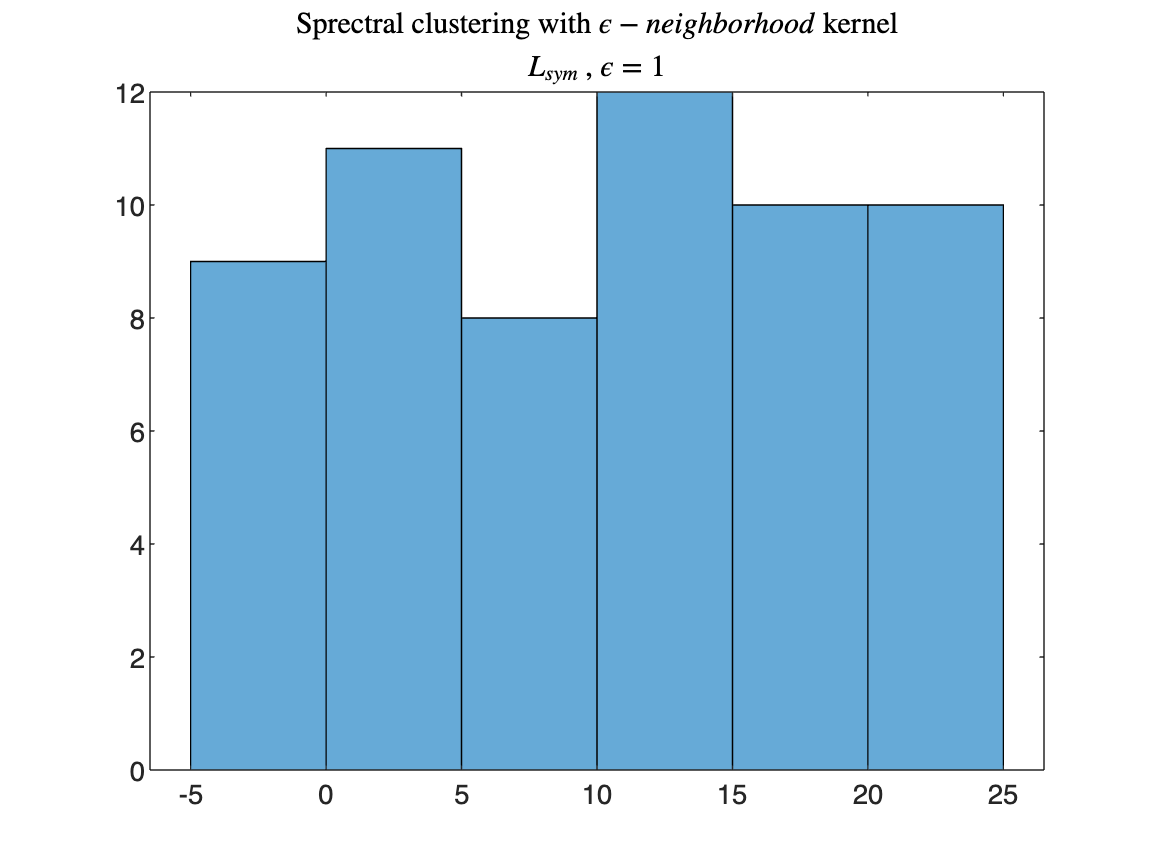

P=laplacian_sym(epsilon_kernel(Z,1),3);
histogram(Z(P==1))
hold on
histogram(Z(P==2))
histogram(Z(P==3))
title('Sprectral clustering with $\epsilon - neighborhood$ kernel', ...
    '$L_{sym}$ , $\epsilon = 1$','interpreter','latex')
hold off

## Normalized Laplacian

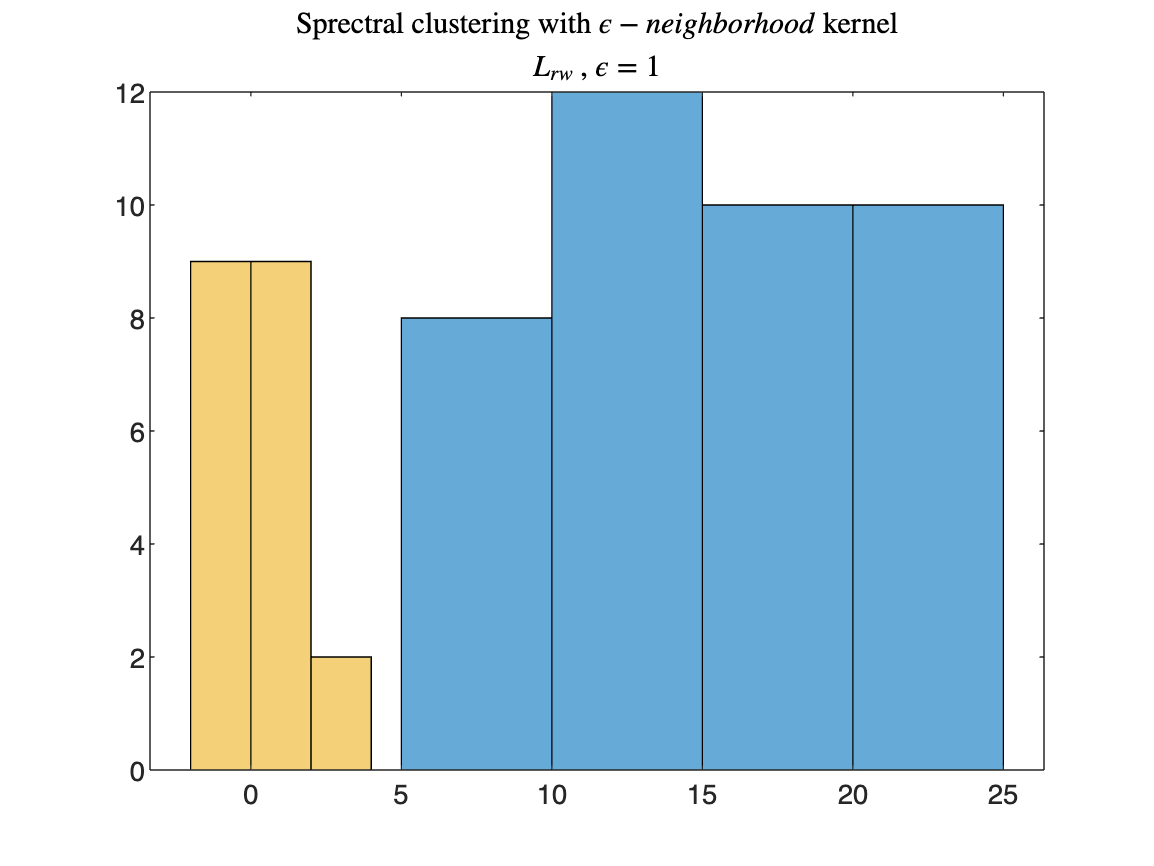

P=laplacian_rw(epsilon_kernel(Z,1),3);
histogram(Z(P==1))
hold on
histogram(Z(P==2))
histogram(Z(P==3))
title('Sprectral clustering with $\epsilon - neighborhood$ kernel', ...
    '$L_{rw}$ , $\epsilon = 1$','interpreter','latex')
hold off

## Normalized cuts

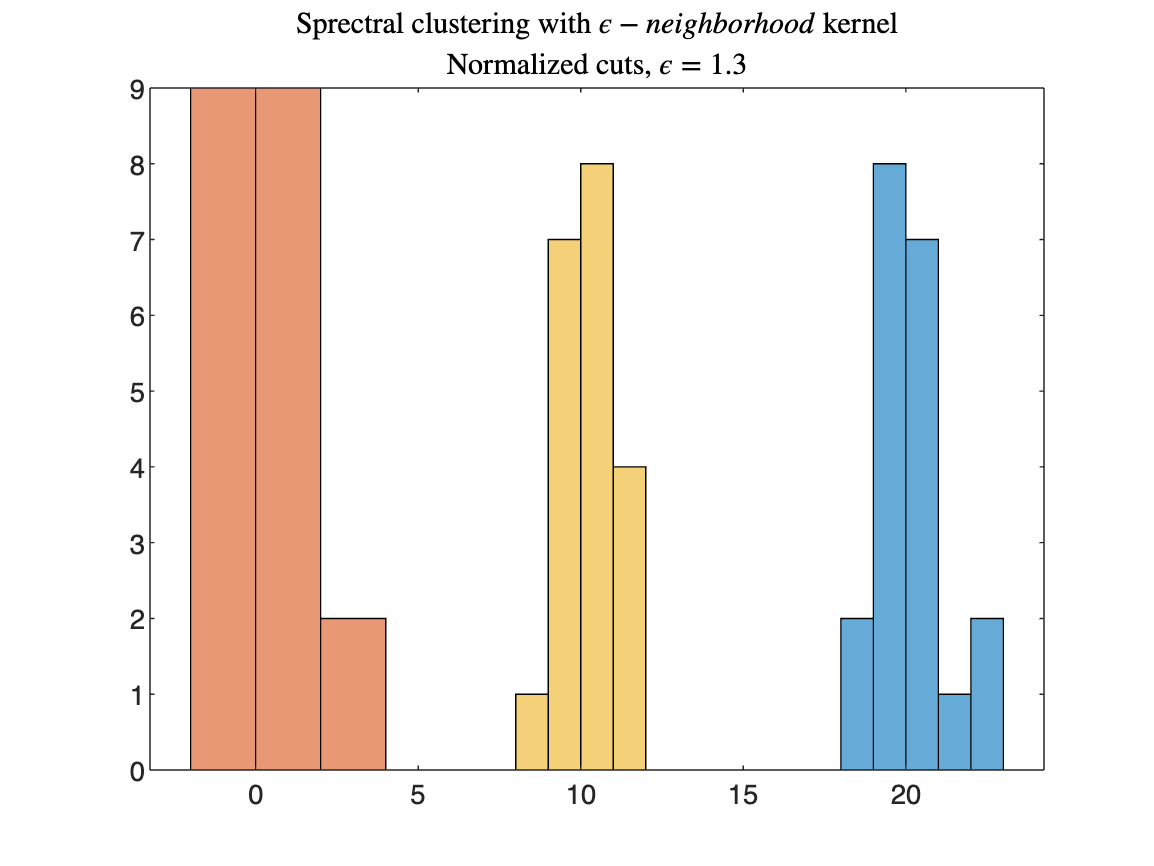

P=normalized_cuts(epsilon_kernel (Z,1.3),3);
histogram(Z(P==1))
hold on
histogram(Z(P==2))
histogram(Z(P==3))
title('Sprectral clustering with $\epsilon - neighborhood$ kernel' , ...
    'Normalized cuts, $\epsilon = 1.3$','interpreter','latex')
hold off

### Conclusion

$\epsilon - neighborhood$ kernels semm to work fine as well, however their problem is the fact that the adjacency matrix is binary, consisting only of zeros and ones so it is harder to clearls detect the clusters.

# Spectral clustering with $\epsilon - neighborhood$ kernels, 2D data

## Unnormalized Laplacian

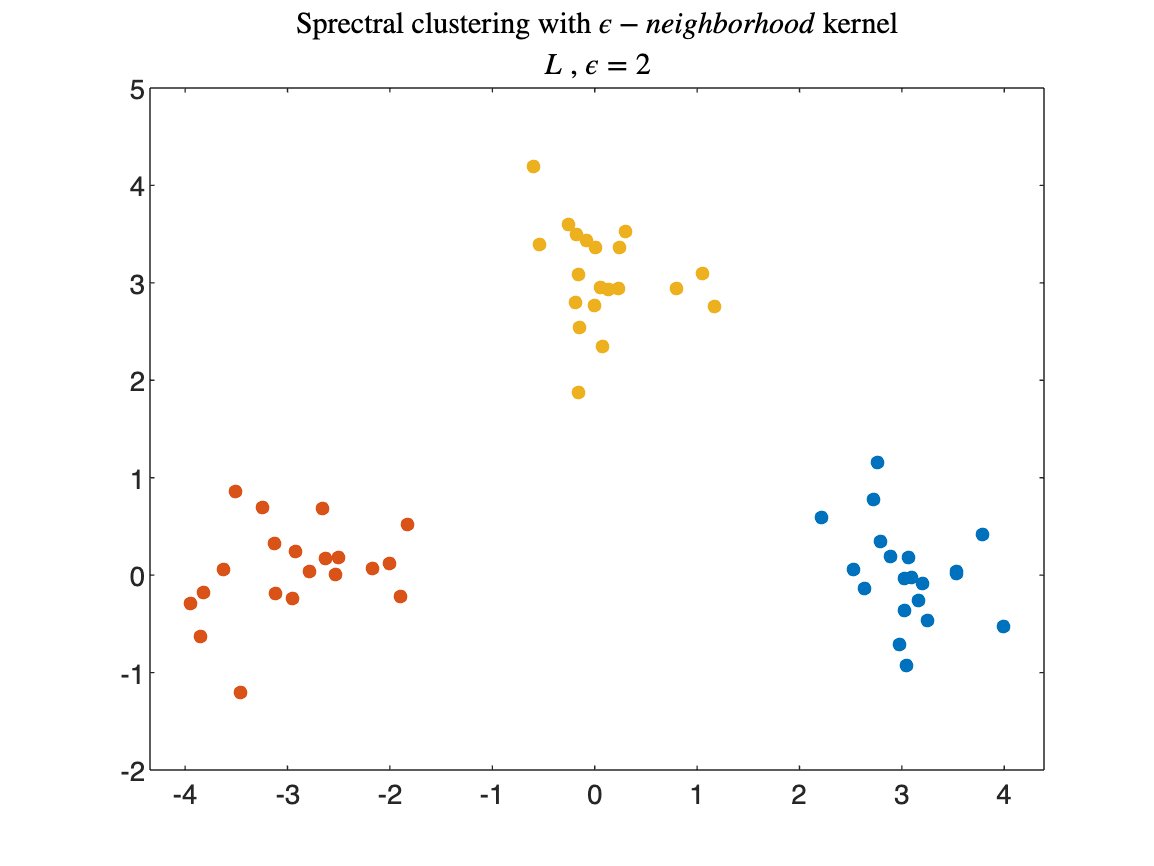

P=laplacian(epsilon_kernel (X,2),3);
gscatter(X1,X2,P) 
title('Sprectral clustering with $\epsilon - neighborhood$ kernel', ...
    '$L$ , $\epsilon = 2$','interpreter','latex')
legend('off');
xlabel('')
ylabel('')

## Normalized Laplacian

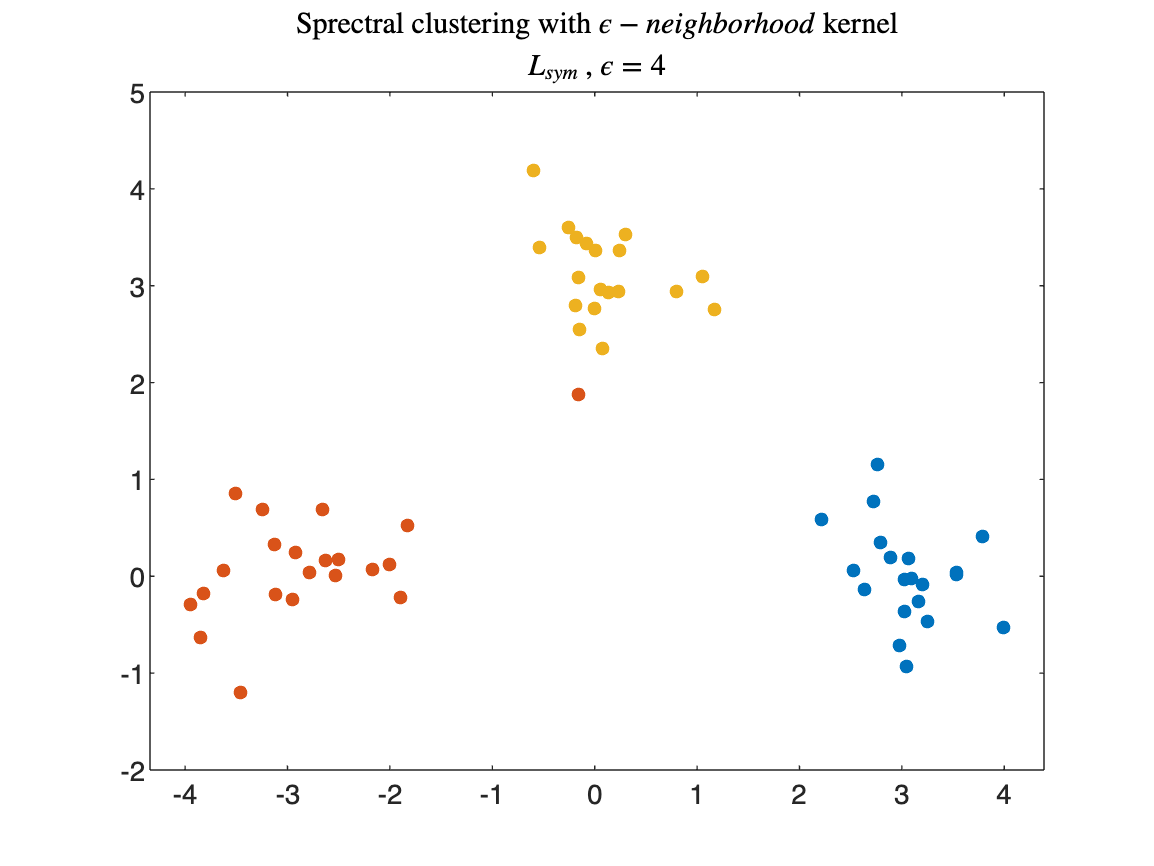

P=laplacian_sym(epsilon_kernel (X,4),3);
gscatter(X1,X2,P) 
title('Sprectral clustering with $\epsilon - neighborhood$ kernel', ...
    '$L_{sym}$ , $\epsilon = 4$','interpreter','latex')
legend('off');
xlabel('')
ylabel('')

## Normalized Laplacian

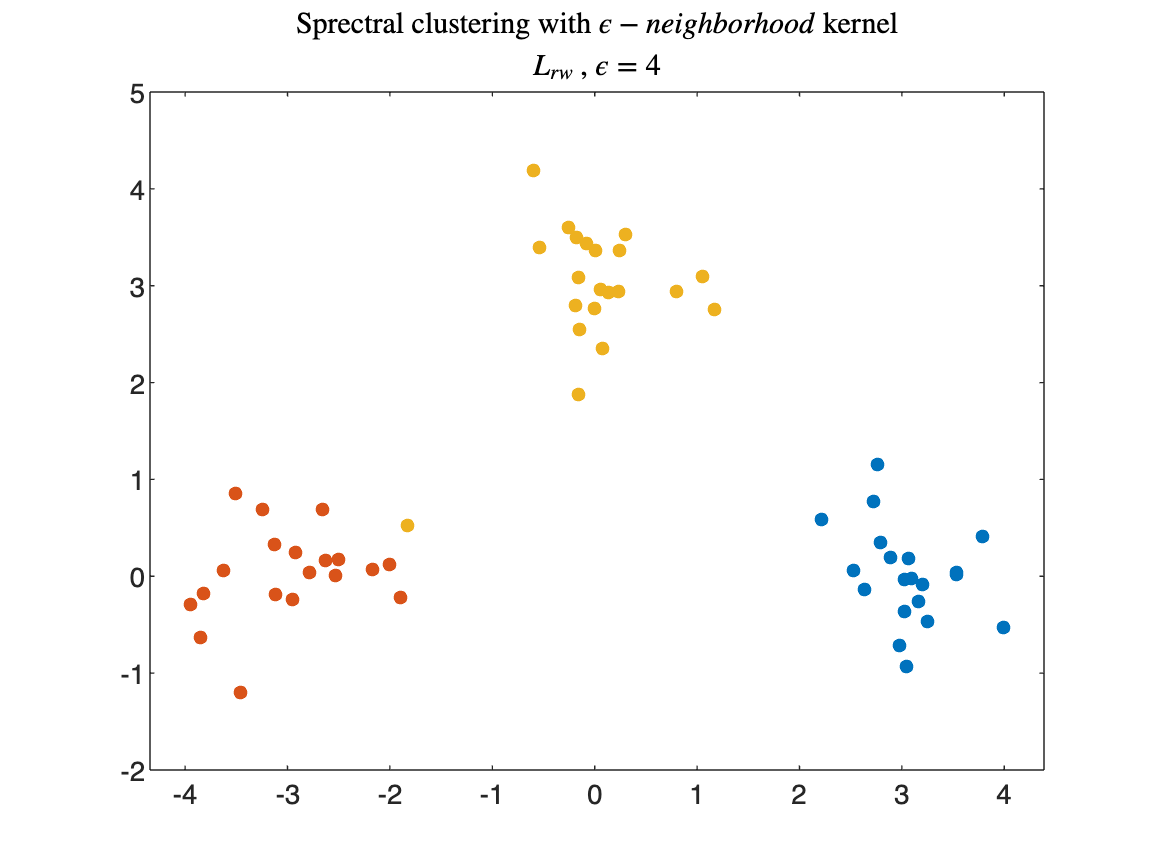

P=laplacian_rw(epsilon_kernel (X,4),3);
gscatter(X1,X2,P) 
title('Sprectral clustering with $\epsilon - neighborhood$ kernel', ...
    '$L_{rw}$ , $\epsilon = 4$','interpreter','latex')
legend('off');
xlabel('')
ylabel('')

## Normalized Cuts

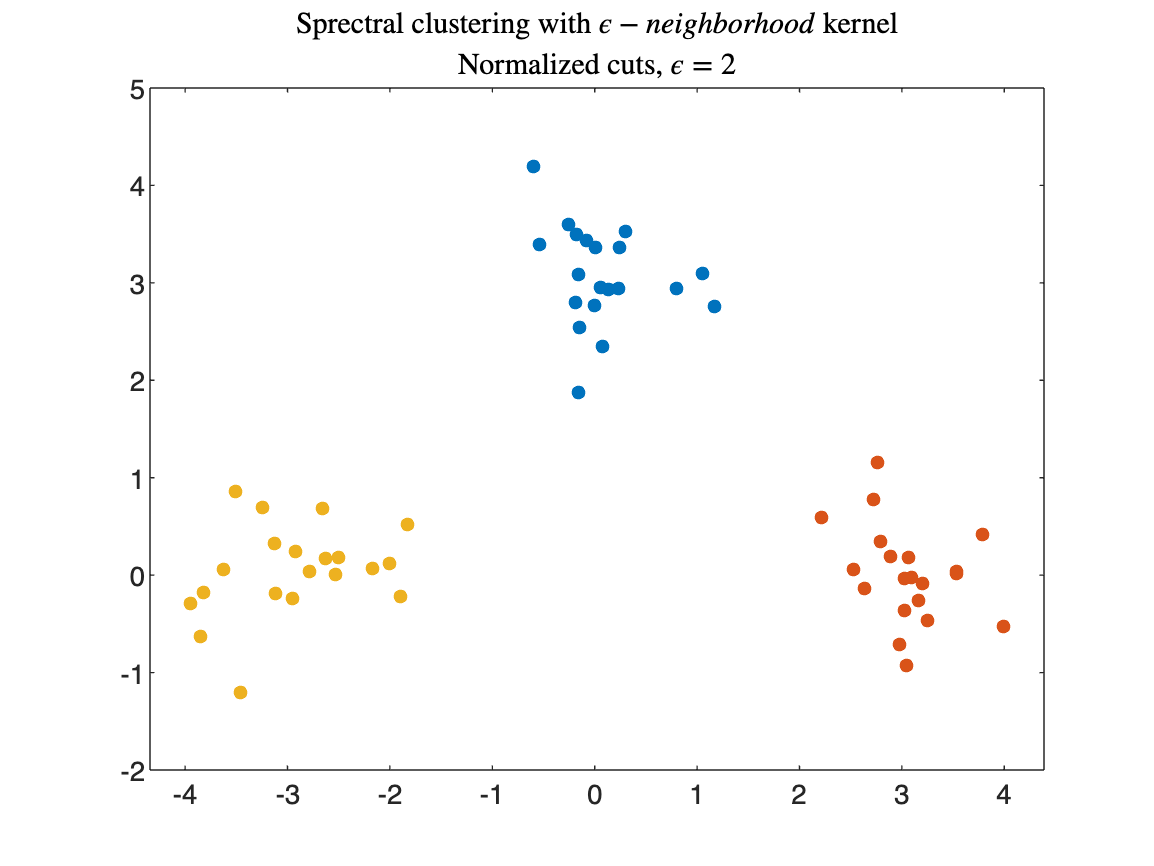

P=normalized_cuts(epsilon_kernel (X,2),3);
gscatter(X1,X2,P) 
title('Sprectral clustering with $\epsilon - neighborhood$ kernel', ...
    'Normalized cuts, $\epsilon = 2$','interpreter','latex')
legend('off');
xlabel('')
ylabel('')

### Conclusion

Luckily, 2D data classification went prefect!

# Spectral clustering with $\epsilon - neighborhood$ kernels, Spiral data

## Unnormalized Laplacian

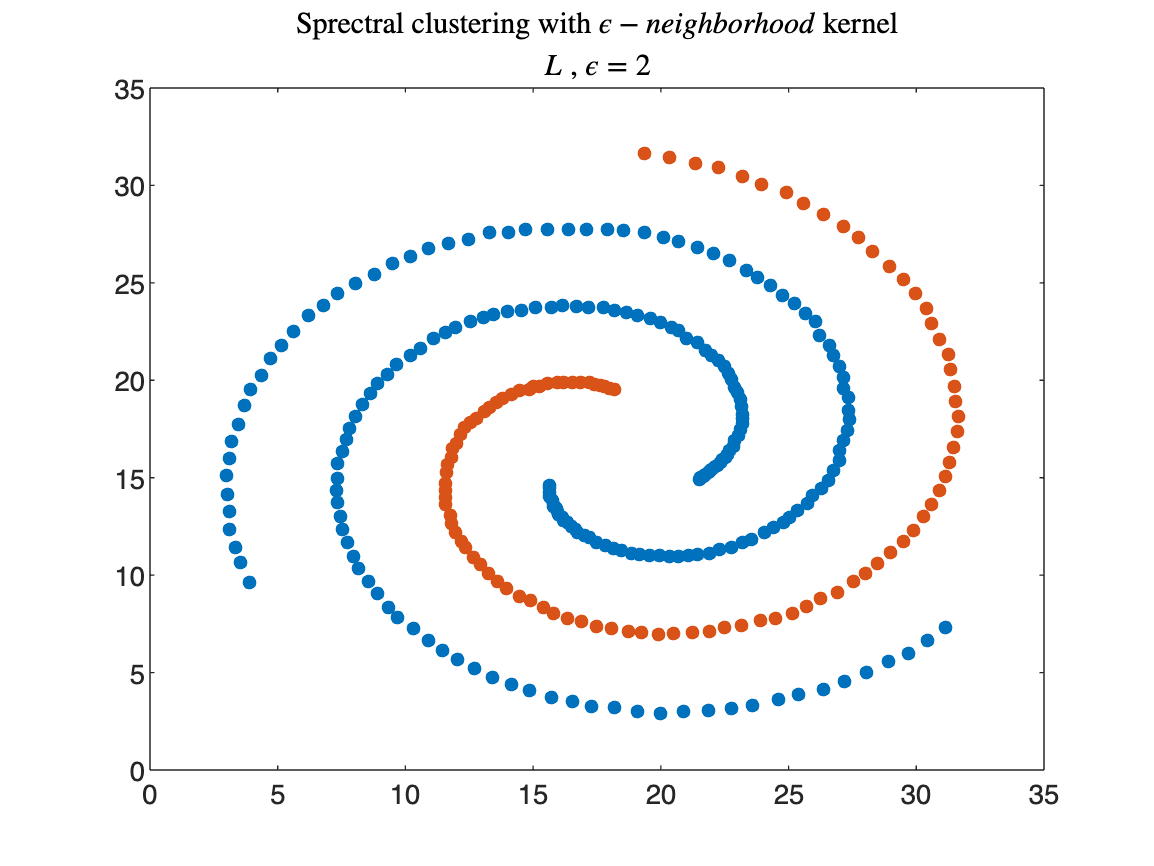

P=laplacian(epsilon_kernel (A,2),3);
gscatter(A1,A2,P) 
title('Sprectral clustering with $\epsilon - neighborhood$ kernel', ...
    '$L$ , $\epsilon = 2$','interpreter','latex')
legend('off');
xlabel('')
ylabel('')

## Symetric Laplacian

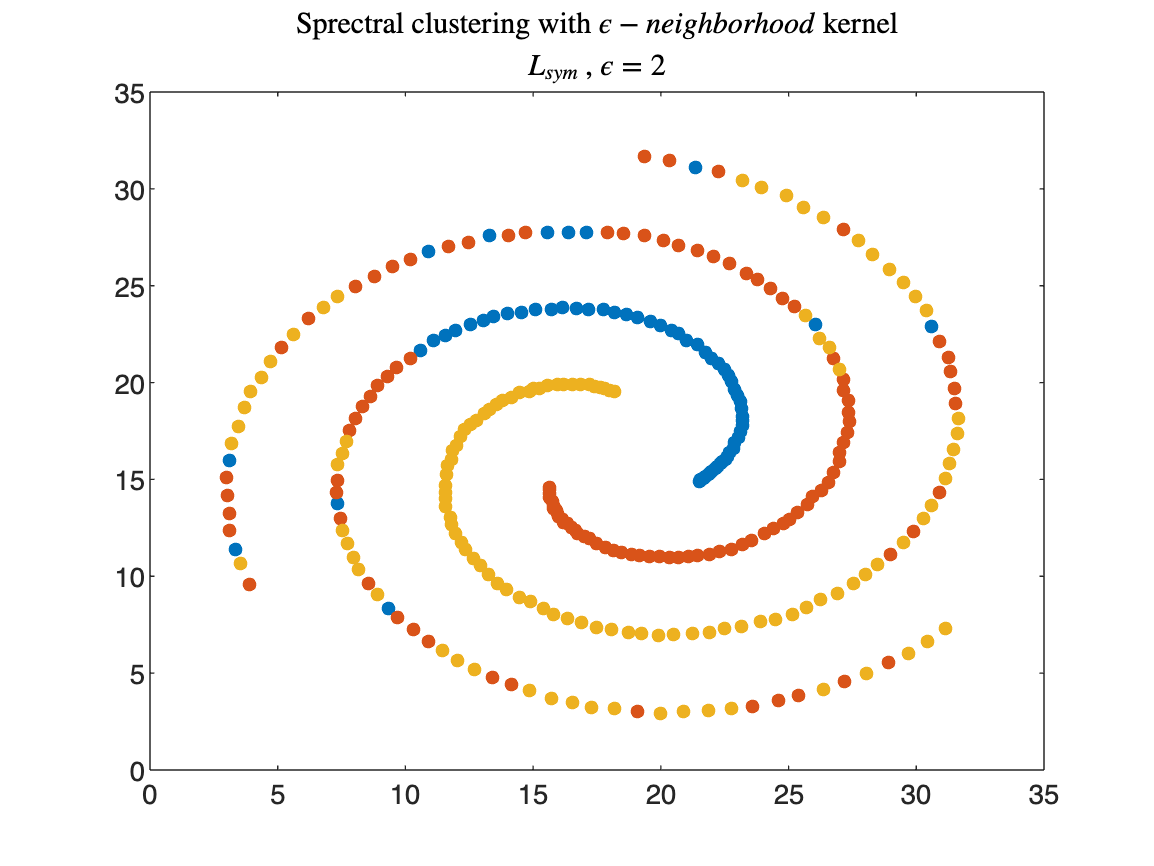

P=laplacian_sym(epsilon_kernel (A,2),3);
gscatter(A1,A2,P) 
title('Sprectral clustering with $\epsilon - neighborhood$ kernel', ...
    '$L_{sym}$ , $\epsilon = 2$','interpreter','latex')
legend('off');
xlabel('')
ylabel('')

## Normalized Laplacian

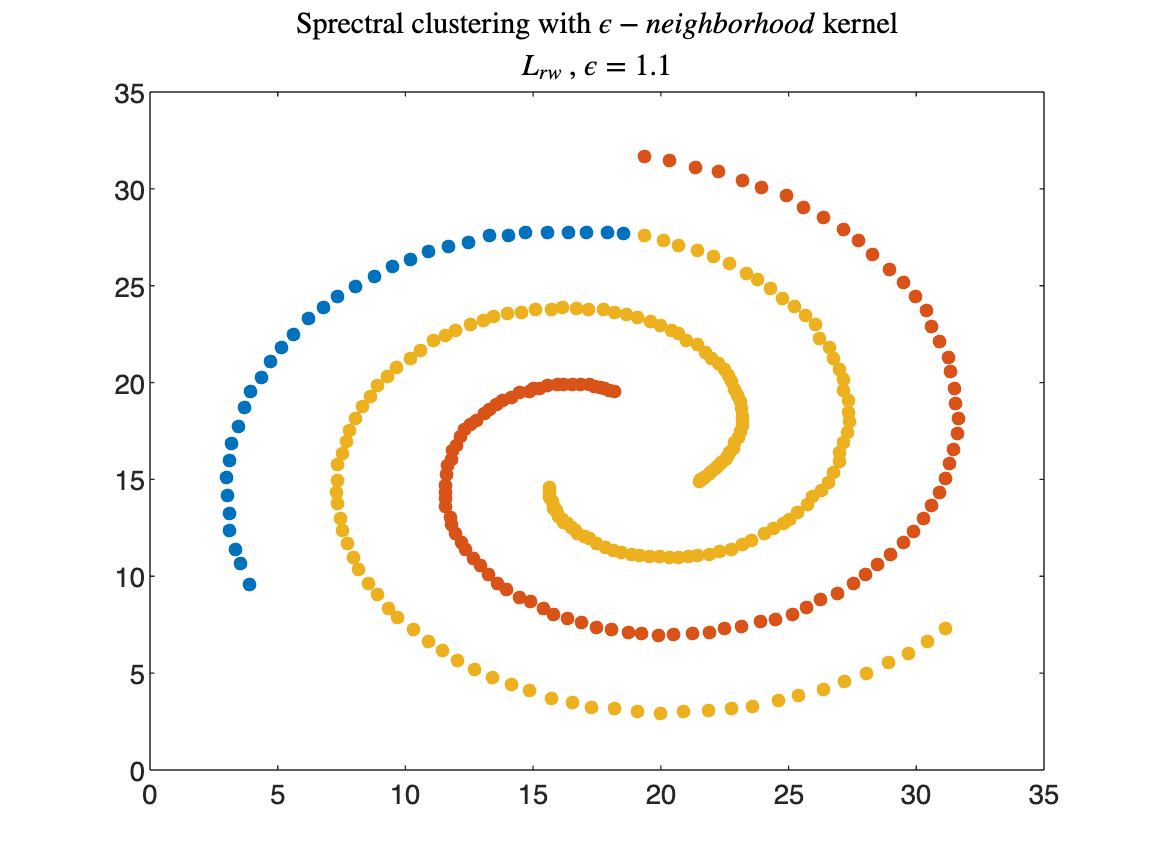

P=laplacian_rw(epsilon_kernel (A,1.3),3);
gscatter(A1,A2,P) 
title('Sprectral clustering with $\epsilon - neighborhood$ kernel', ...
    '$L_{rw}$ , $\epsilon = 1.1$','interpreter','latex')
legend('off');
xlabel('')
ylabel('')

## Normalized Cuts

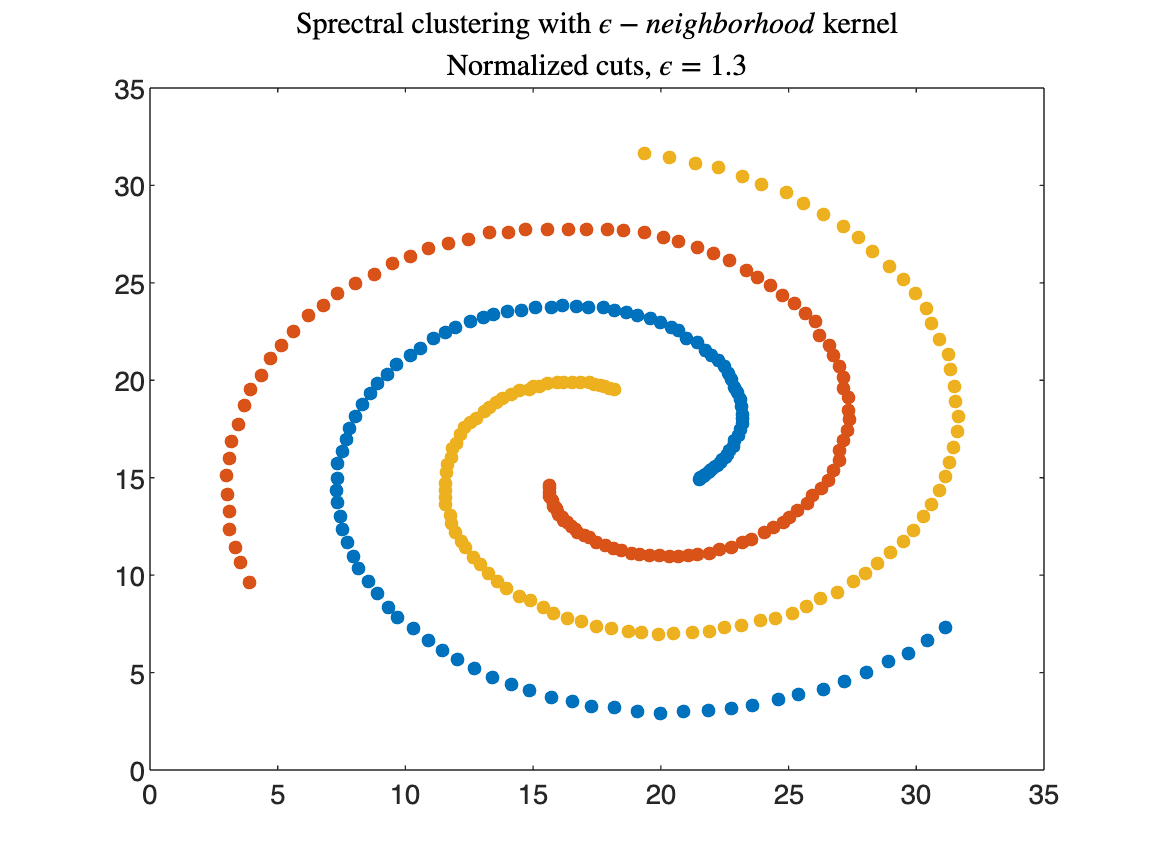

P=normalized_cuts(epsilon_kernel (A,1.3),3);
gscatter(A1,A2,P) 
title('Sprectral clustering with $\epsilon - neighborhood$ kernel', ...
    'Normalized cuts, $\epsilon = 1.3$','interpreter','latex')
legend('off');
xlabel('')
ylabel('')

### Conclusion

The spiral data seem to cause some problems when using the $\epsilon - neighborhood$ kernels. Interestingly we seem to find the $\epsilon$ parameter for normalized cuts in most of our problems so far, unlike the other methods. Normalized cuts algorithm is the fastest one as well.

# Spectral clustering with $\epsilon - neighborhood$ kernels, Ring data

## Unnormalized Laplacian

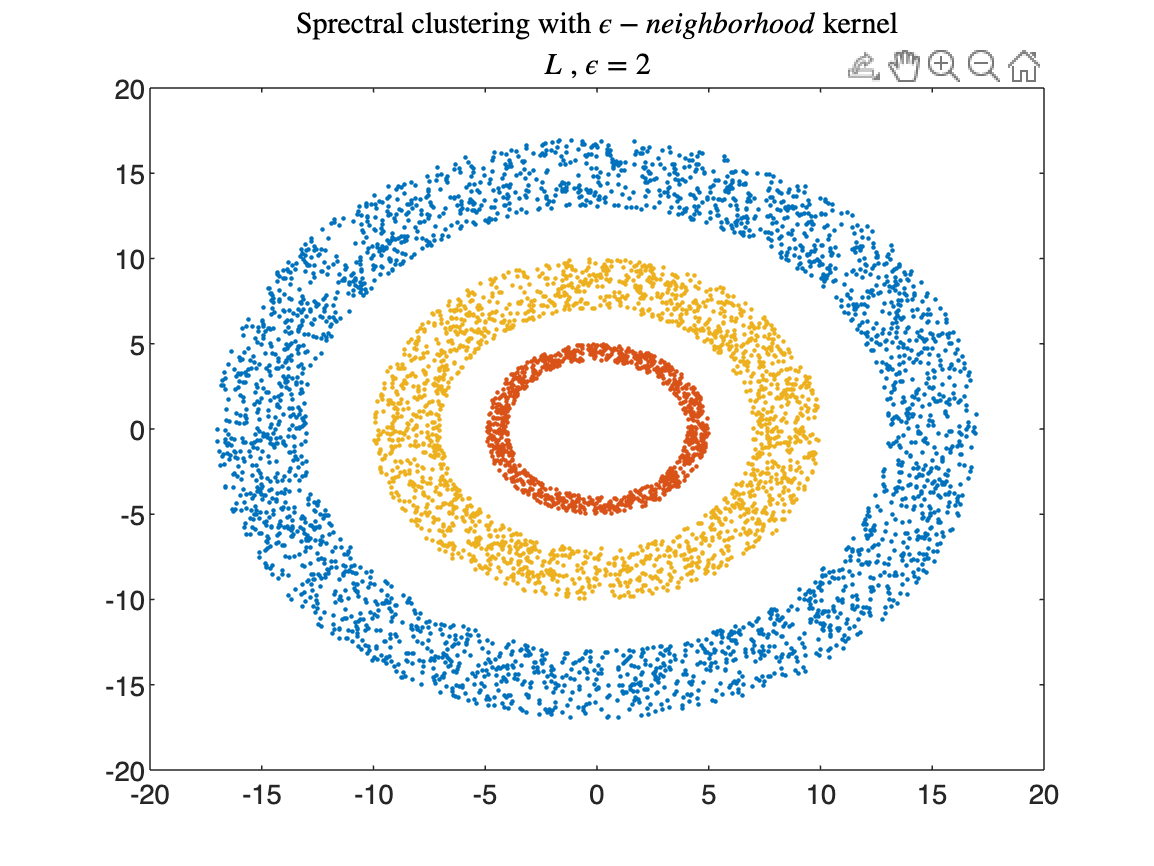

P=laplacian(epsilon_kernel (K,1.5),3);
gscatter(K1,K2,P) 
title('Sprectral clustering with $\epsilon - neighborhood$ kernel', ...
    '$L$ , $\epsilon = 2$','interpreter','latex')
legend('off');
xlabel('')
ylabel('')

## Symetric Laplacian

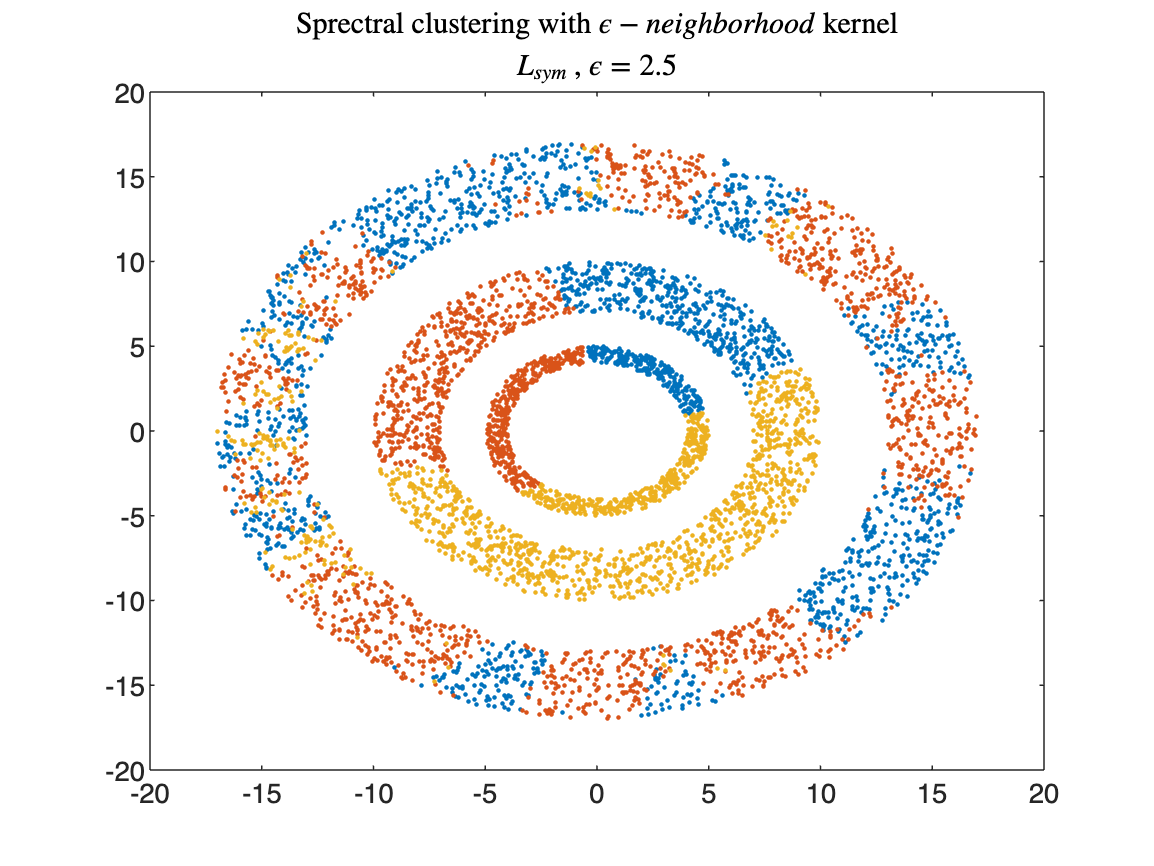

P=laplacian_sym(epsilon_kernel (K,2.5),3);
gscatter(K1,K2,P) 
title('Sprectral clustering with $\epsilon - neighborhood$ kernel', ...
    '$L_{sym}$ , $\epsilon = 2.5$','interpreter','latex')
legend('off');
xlabel('')
ylabel('')

## Normalized Laplacian

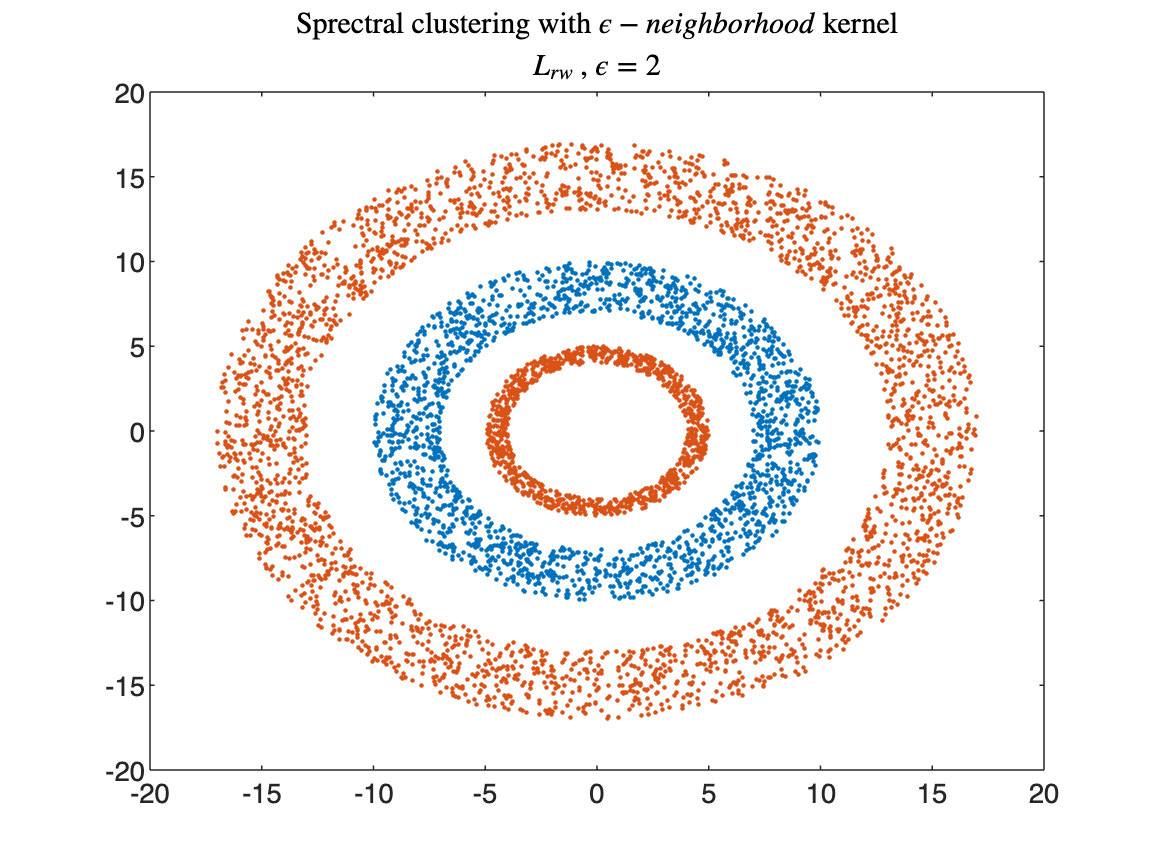

P=laplacian_rw(epsilon_kernel (K,2),3);
gscatter(K1,K2,P) 
title('Sprectral clustering with $\epsilon - neighborhood$ kernel', ...
    '$L_{rw}$ , $\epsilon = 2$','interpreter','latex')
legend('off');
xlabel('')
ylabel('')

## Normalized Cuts

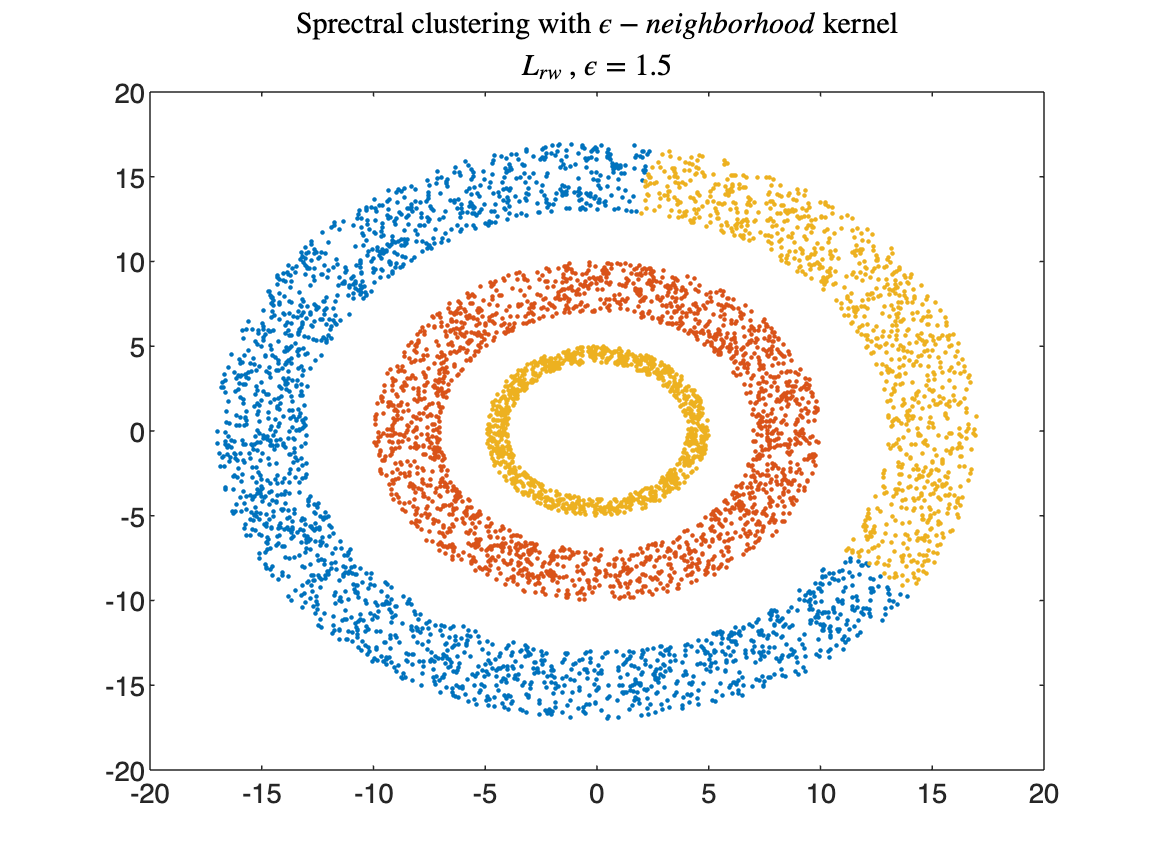

P=normalized_cuts(epsilon_kernel (K,1.5),3);
gscatter(K1,K2,P) 
title('Sprectral clustering with $\epsilon - neighborhood$ kernel', ...
    '$L_{rw}$ , $\epsilon = 1.5$','interpreter','latex')
legend('off');
xlabel('')
ylabel('')

### Conclusion

The three rings are the most difficult taks and, unfortunately, proove to be too much for 

$\epsilon$-neighborhood kernels.

## Note on meassuring preformance of Gaussian kernel calculation.

f1=@() gaussian_kernel([K ; K],2)

f1 = function_handle with value:
    @()gaussian_kernel([K;K],2)


t1=timeit(f1)

t1 = 1.5845

f2=@() gaussian_kernel2([K ; K],2)

f2 = function_handle with value:
    @()gaussian_kernel2([K;K],2)


t2=timeit(f2)

t2 = 1.8443

f3=@() gaussian_kernel3([K ; K],2)

f3 = function_handle with value:
    @()gaussian_kernel3([K;K],2)


t3=timeit(f3)

t3 = 11.5705

For this reason, *gaussian_kernel *is the prefered function*.*